# Processor-in-the-Loop Automotive Controller on an Arm Cortex-M7 Fast Model Emulator

## PID-Based ABS Controller: PIL Verification on an Arm® Cortex®-M7 Fast Model Emulator

Project Number : 257

## 1. Introduction 

This report presents the development and validation of a high-performance PID-based Anti-lock Braking System (ABS) controller using a Model-Based Design (MBD) workflow in MATLAB and Simulink. The project focuses on bridging the gap between control system design and embedded implementation through systematic verification stages.

The core innovation lies in the Processor-in-the-Loop (PIL) verification conducted on an Arm Cortex-M7 Fast Model Emulator (FVP). By utilizing a cycle-accurate virtual prototype instead of physical hardware, the following was achieved:

- **Deterministic Execution:** Verified the PID control law's numerical fidelity against the golden reference model (MIL) in a bit-true environment. 

- **Early-Stage Performance Benchmarking:** Captured execution profiling metrics such as task execution time (TET) and CPU utilization on the virtual Arm target, enabling early optimization. 

- **Digital Traceability:** Established a continuous link from high-level model design to the generated C code executed within the emulator. 

Overall, the project demonstrates a complete model-to-processor validation workflow, ensuring both functional correctness and performance reliability of the embedded ABS controller without requiring physical hardware.

## 2. Selection of Application: Anti-Lock Braking System (ABS)

For this project, the [**Anti-Lock Braking System (ABS)**](https://www.mathworks.com/help/simulink/slref/modeling-an-anti-lock-braking-system.html) Simulink example was selected. ABS is a safety-critical system that prevents wheel lock-up during braking, helping maintain vehicle stability and control.

The focus is on the **controller subsystem**, which regulates braking force to maintain optimal slip. This subsystem is used for simulation (MIL), code generation, and Processor-in-the-Loop (PIL) verification on the Arm Cortex-M7 FVP, enabling validation of both control performance and embedded implementation.

## 3. Modifications to the Application 

To meet the defined performance requirements, the existing ABS controller was analyzed and modified. The model was simulated while logging key signals such as slip ratio, vehicle speed, and braking response to evaluate system behavior.

Based on the observed performance, the controller was enhanced by **integrating a **[**PID**](https://in.mathworks.com/help/control/ug/proportional-integral-derivative-pid-controllers.html)** controller** to achieve better regulation of the slip ratio. The PID parameters were carefully tuned to ensure:

- Stable braking without wheel lock-up 

- Fast and smooth response to changing conditions 

- Maintenance of the desired slip target ( **μ **)

This modification improved the overall control performance, ensuring that the ABS system meets both functional and dynamic requirements.

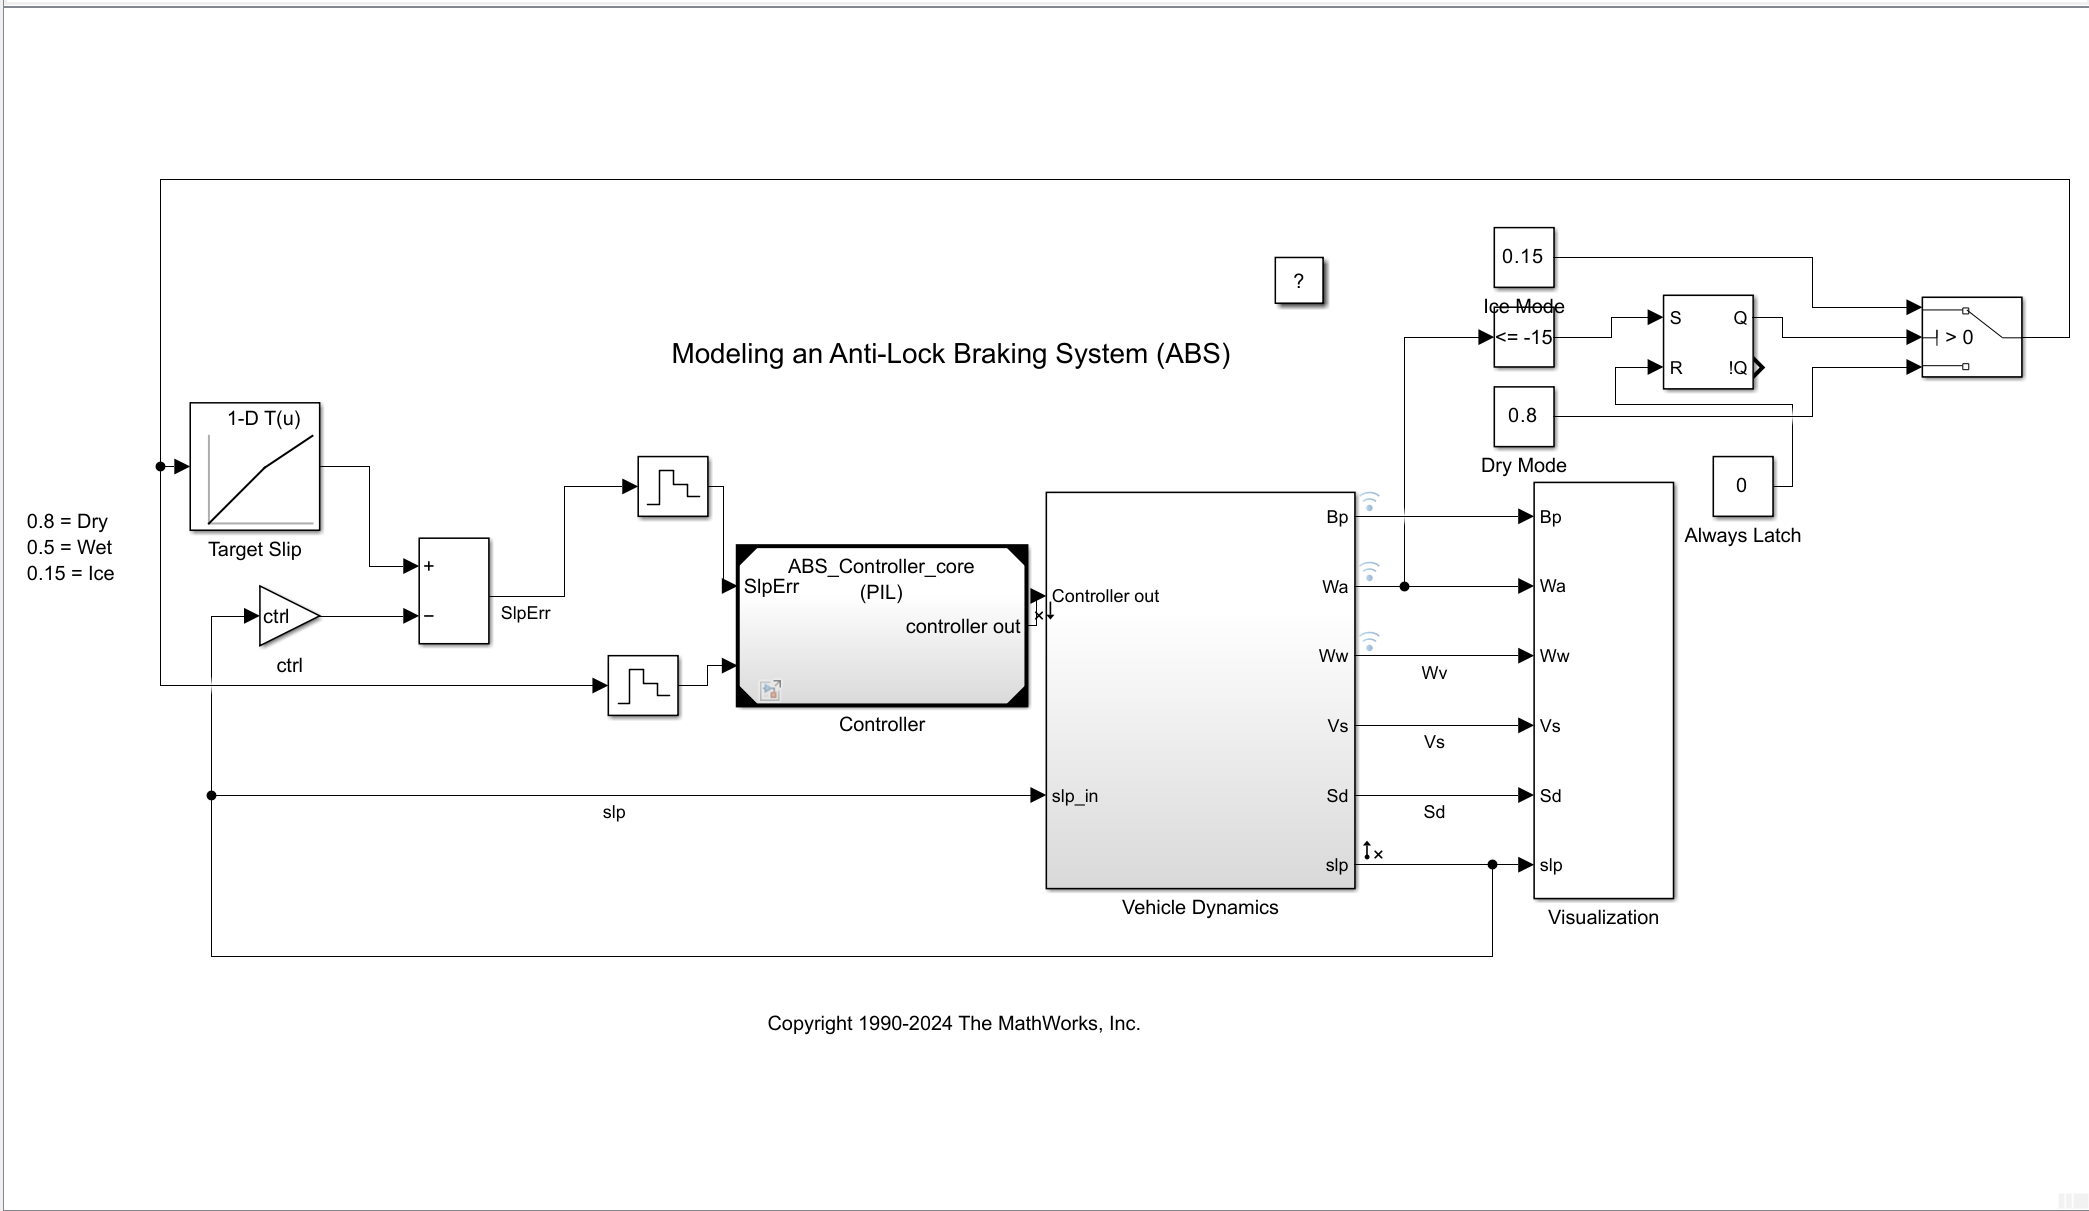

*Fig -1 ABS Simulink Model *

## 4. Comparative Analysis of Controller Performance

To evaluate the effectiveness of the implemented controller, simulations were performed under three conditions:

- Without ABS (Baseline)

- With ABS (default controller) 

- With ABS + PID controller  

The corresponding results are shown in the figures below.

The comparison highlights that:

- **Without ABS:** Wheel lock-up occurs, leading to poor stability and longer stopping distance. 

- **With ABS (default):** Wheel lock is reduced, but the response may not be optimal. 

- **With ABS + PID:** Improved slip regulation, smoother braking response, and better control over stopping behavior. 

These results demonstrate that the addition and tuning of the PID controller significantly enhance the performance of the ABS system.

**a) Without ABS** **(** **μ = 0.8 )**

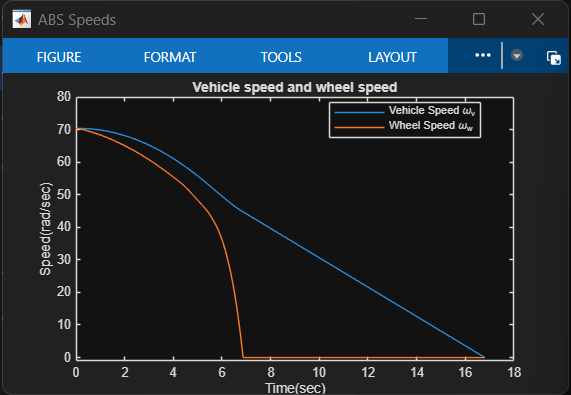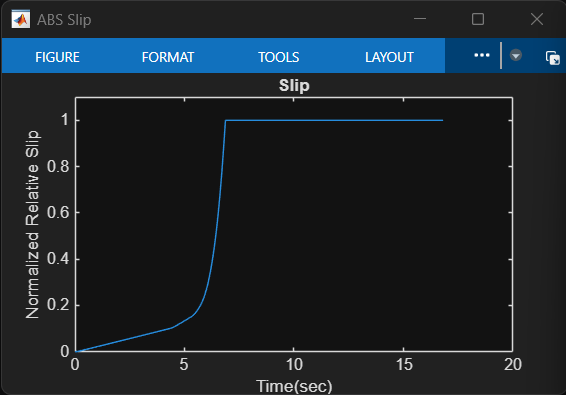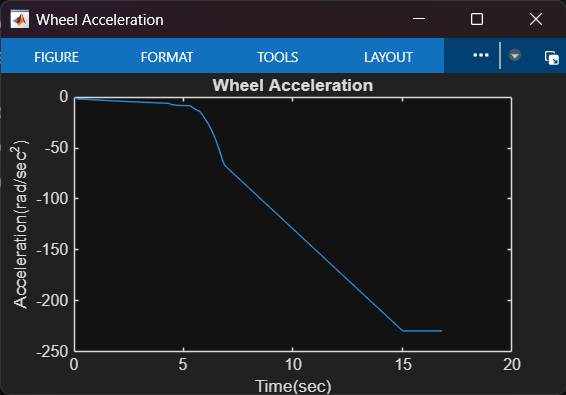

**b) With ABS ( μ  = 0.8 )**

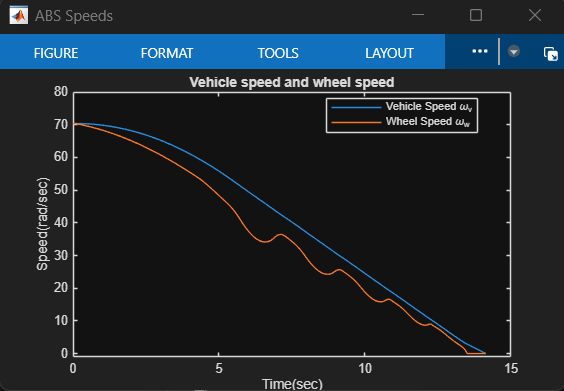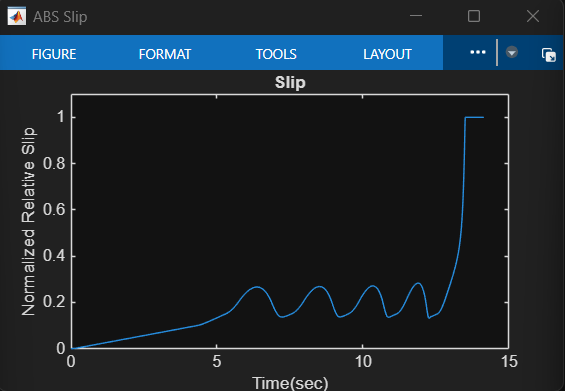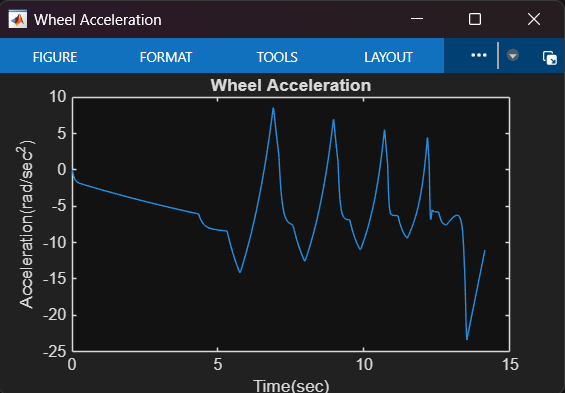

**c) With ABD + PID Controller ( μ = 0.8 )**

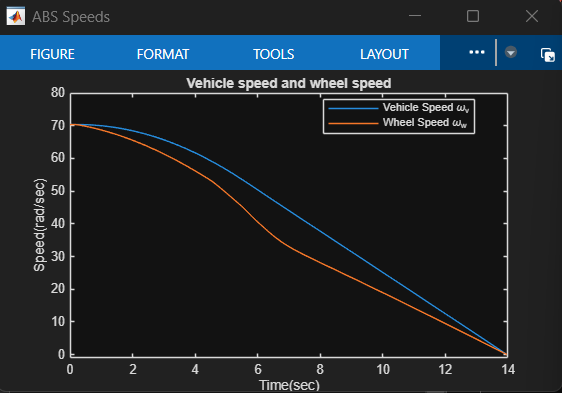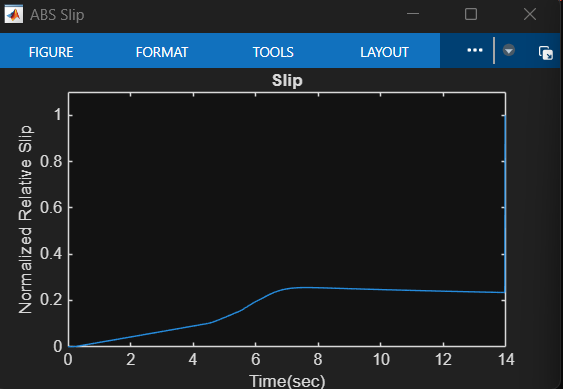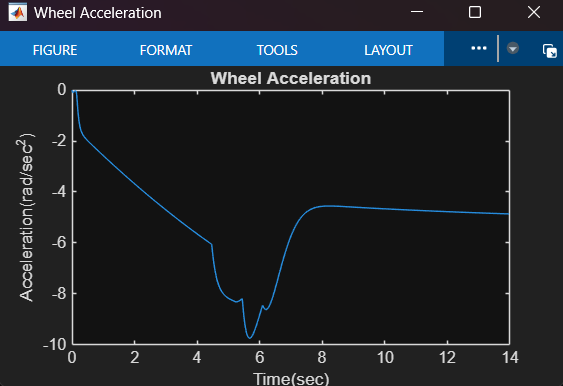

## 5. Results with PID Controller (Dry, Wet, Ice Conditions)

The ABS controller with the tuned PID was tested under three road conditions: dry (μ ≈ 0.8), wet (μ ≈ 0.5), and ice (μ ≈ 0.15). The results show that the PID controller effectively regulates the slip ratio according to the target values for each surface.

- **Dry Road:** Higher friction allows quicker stabilization, and the controller maintains slip near the desired value with fast response. 

- **Wet Road:** The controller adapts to reduced friction, showing slightly slower response but stable slip control. 

- **Ice Road:** Due to very low friction, the response is slower, but the PID still prevents wheel lock and maintains controlled braking. 

Overall, the PID controller improves stability and ensures appropriate slip regulation across varying road conditions.

run_abs_pid_base         % Execute Basic Conditions of slip    

  ABS MIL & PIL VERIFICATION CAMPAIGN
  Model : sldemo_absbrake
  Date  : 2026-04-30 14:29:26
  Output Directory : .\MIL_PIL_Results\

--- Phase A : 3-road core test (MIL Baseline) ---



[Dry] mu_peak=0.80  slipTgt=0.20  maxSlip=0.246  stopON=774.4 ft  stopOFF=815.5 ft  saves=5.0%  PASS


[Wet] mu_peak=0.50  slipTgt=0.15  maxSlip=0.233  stopON=1107.5 ft  stopOFF=1279.3 ft  saves=13.4%  PASS


[Ice] mu_peak=0.15  slipTgt=0.10  maxSlip=0.220  stopON=2013.2 ft  stopOFF=2106.4 ft  saves=4.4%  FAIL

--- Phase C : Reporting ---



## 5. Requirements Definition

**REQ-01: ABS Stopping Distance Reduction**

The ABS controller must reduce the total vehicle stopping distance by at least 3% compared to braking without ABS across all road conditions (dry, wet, and ice). This requirement ensures that the ABS system achieves its primary safety objective of improving braking efficiency and vehicle control.

**REQ-02: Optimal Wheel Slip Regulation**

The controller must regulate brake pressure to maintain the wheel slip ratio close to the desired target value for each road condition. The maximum slip must not exceed the target by more than 0.15, ensuring effective traction and preventing wheel lock-up.

**REQ-03: Numerical Equivalence (MIL vs PIL)**

The generated embedded C code executed on the Arm Cortex-M7 (PIL) must produce results equivalent to the Simulink model (MIL). This ensures that code generation and target execution do not introduce numerical errors or inconsistencies.

**REQ-04: CPU Utilization Constraint**

The ABS controller must execute within real-time constraints, ensuring that CPU utilization remains below 70% for a sampling time of 10 ms. This guarantees that the controller can operate reliably alongside other tasks in an automotive ECU.

**REQ-05: Controller Output Limits**

The controller output must remain within physically valid brake pressure limits throughout operation. This prevents unrealistic control signals and ensures stable and safe actuator behavior.

**REQ-08: ABS Deactivation Behavior**

When the ABS system is disabled, the controller must not influence brake pressure, and the system should behave as a standard braking system. This ensures correct enable/disable functionality.

**REQ-10: Wheel Lockup Prevention**

The ABS controller must prevent complete wheel lock-up by ensuring that the slip ratio does not exceed a critical threshold (typically below 1). This requirement is essential for maintaining vehicle stability and steering control.

**Verified Requiremets **

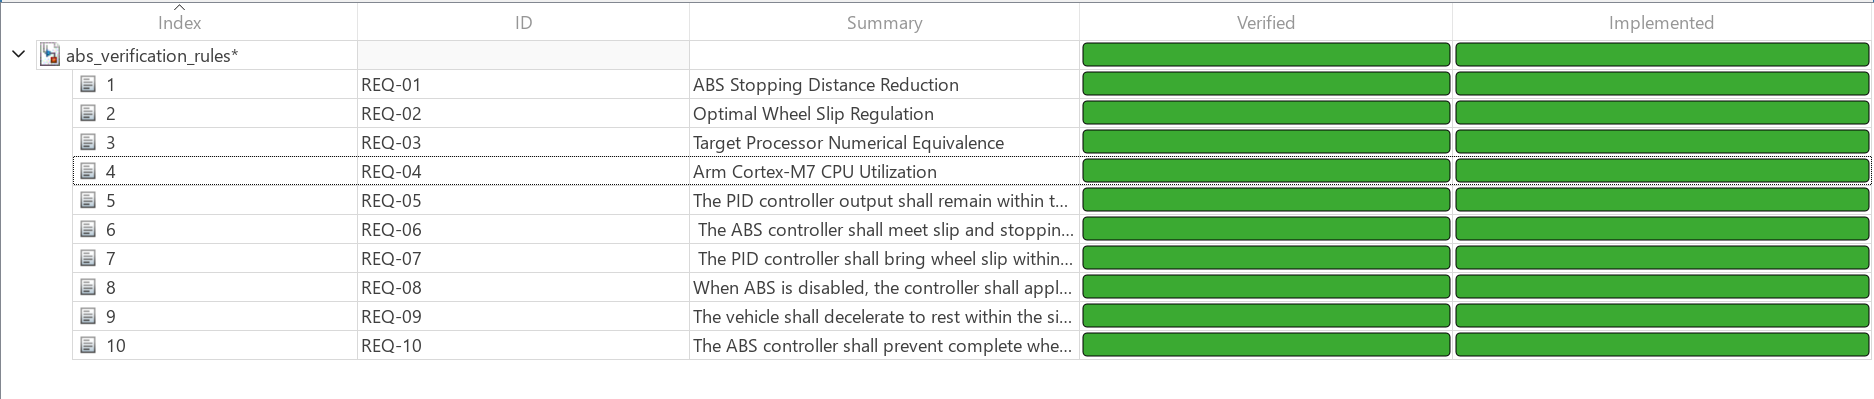

**Tracability Matrix**

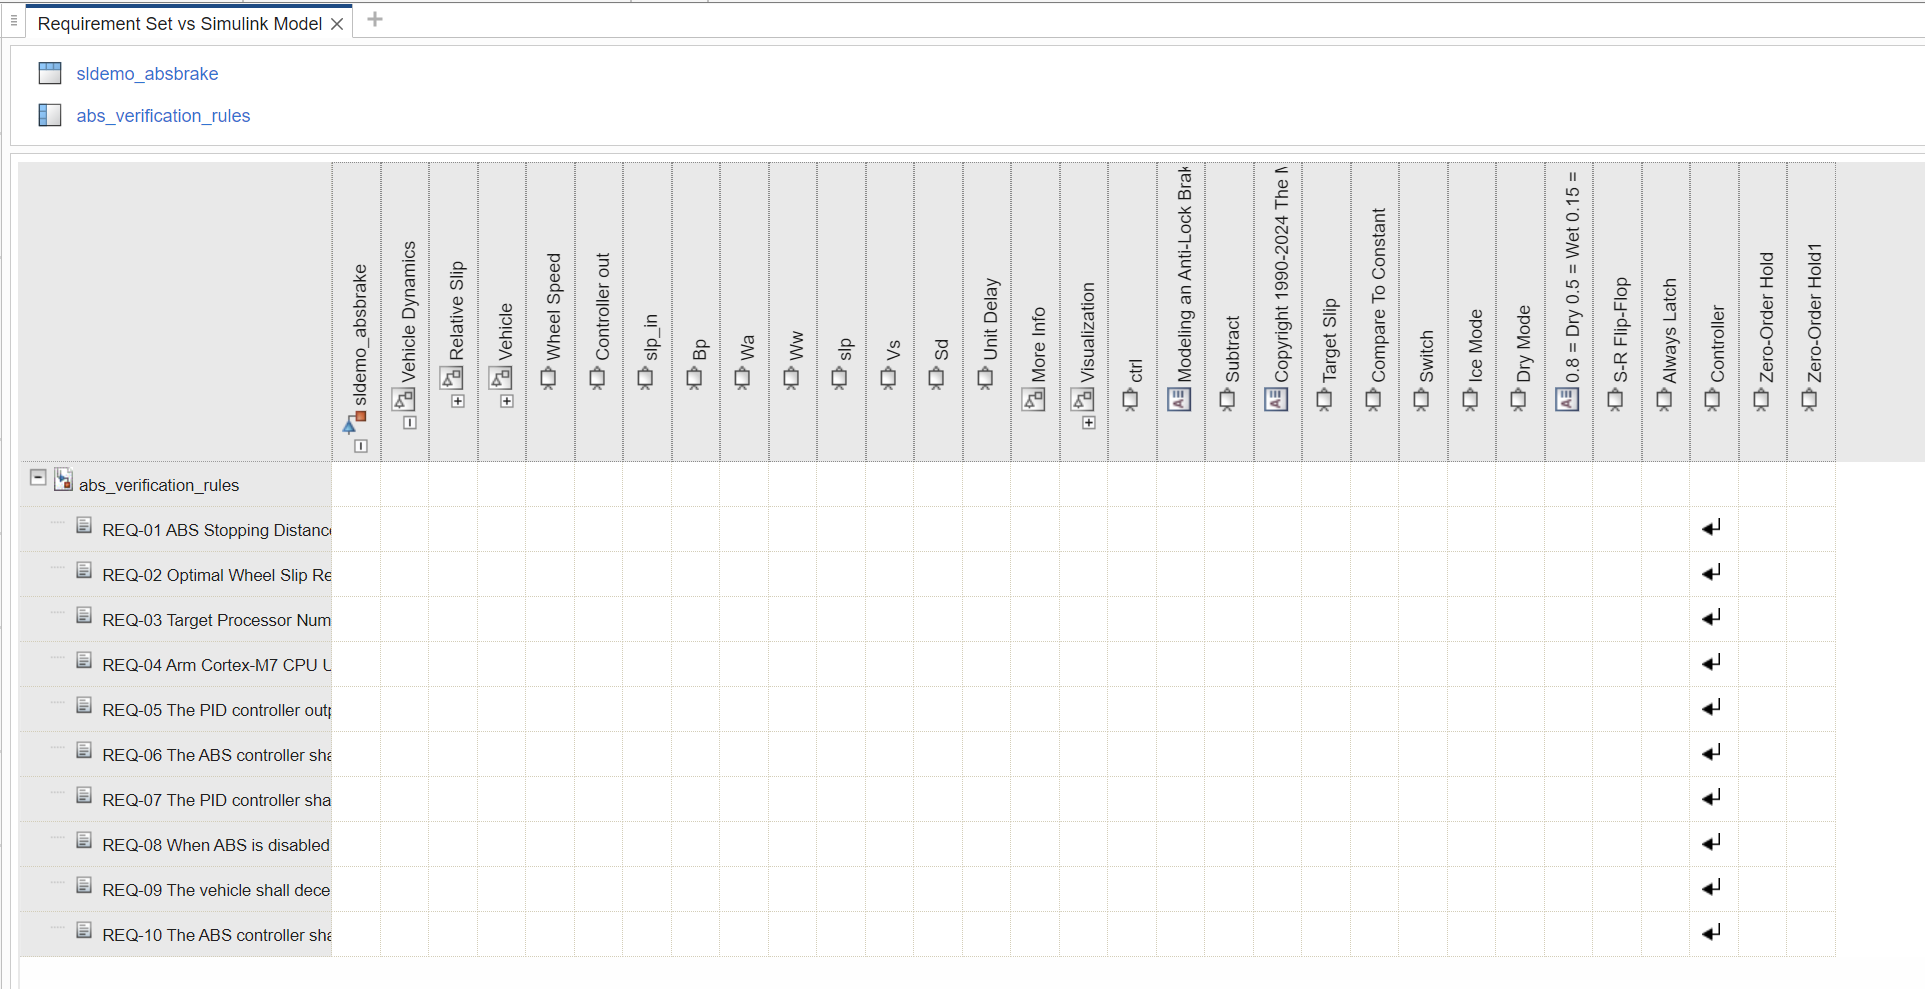

## 6. Processor-in-the-Loop (PIL) Setup and Configuration

The Processor-in-the-Loop (PIL) verification was performed using [Arm Development Studio (DS000B)](https://developer.arm.com/downloads/view/DS000B?sortBy=availableBy&revision=r25p1-00rel1-1) version 2025.1-1. This environment was used for compiling, building, and executing the generated embedded C code.

A Fixed Virtual Platform (FVP), specifically the FVP_MPS2_Cortex-M7 emulator, was used as the target processor. This virtual platform accurately models the behavior of an Arm Cortex-M7 microcontroller, allowing execution without requiring physical hardware.

In the PIL setup, the controller designed in Simulink was automatically converted into C code using [Embedded Coder](https://in.mathworks.com/help/ecoder/index.html). This generated code was then compiled and executed on the Cortex-M7 virtual processor using Arm Development Studio.

During simulation, Simulink communicates with the virtual processor, sending input signals and receiving output responses. This enables direct comparison between Model-in-the-Loop (MIL) and [Processor-in-the-Loop (PIL)](https://in.mathworks.com/help/ecoder/processor-in-the-loop.html) results.

**Installed Toolchain Components** 

- Installed **Arm Cortex-M Fast Model Support Package** from MATLAB Add-On Explorer→ Provides access to FVP (Fixed Virtual Platform) emulators for virtual processor execution 

- Installed **Arm Compiler Support Package**→ Enables code generation and compilation for Arm Cortex-M targets 

- These packages enable seamless integration between **MATLAB/Simulink** and **Arm Development Studio**

- Used for executing **Processor-in-the-Loop (PIL)** simulations on the **FVP_MPS2_Cortex-M7** emulator

**FVP Configuration and Hardware Setup**

**Target Virtual Hardware Configuration**

- Hardware board selected: **Arm Cortex-M7 Fast Model**

- Target processor: **Arm Cortex-M7 (via FVP_MPS2_Cortex-M7 emulator)**

- Code generation target: `ert.tlc`** (Embedded Coder)**

- Device type: **ARM Cortex (ARM compatible)**

**Data Representation Settings**

- Integer size: **32-bit**

- Floating-point: **Single (32-bit), Double (64-bit)**

- Pointer size: **32-bit**

- Byte ordering: **Little Endian**

- Arithmetic behavior: **Signed integer division rounds toward zero**

**Processor Configuration**

- CPU Clock: **1000 MHz (1 GHz)**

- Interrupt Frequency: **1 MHz**

- Largest atomic size: 

- Integer: **Long**

- Floating-point: **Double**

**Additional Settings**

- Arithmetic shift enabled for signed integers 

- Data type configuration aligned with target hardware 

- Hardware settings configured for **real-time simulation compatibility**

**Generated C Code **

The ABS controller model was converted into embedded C code using Embedded Coder. The generated code implements the PID-based control logic along with lookup tables for road condition adaptation and includes saturation to ensure bounded control output.

This code is executed on the Arm Cortex-M7 virtual processor during Processor-in-the-Loop (PIL) testing to validate functional and numerical correctness.

`/* Saturation */`

`if (u0 > 1.0) {`

`  *rty_controllerout = 1.0;`

`} else if (u0 < -1.0) {`

`  *rty_controllerout = -1.0;`

`} else {`

`  *rty_controllerout = u0;`

`}`

The above snippet shows the saturation logic used in the controller to ensure that the output remains within valid bounds. This prevents unrealistic brake commands and improves system stability.

**Code Generation and Storage**

- Embedded C code was generated using **Simulink Embedded Coder**

- The code corresponds to the controller subsystem (`ABS_Controller_core`) 

- Generated files include: 

- `.c` (source file) 

- `.h` (header file) 

- supporting utility files 

- The generated code is stored in the MATLAB working directory under:

`               ..\Model_Folder\slprj\ert\ABS_Controller_core`

This generated code is used for Processor-in-the-Loop (PIL) execution, where it is compiled and run on the Arm Cortex-M7 virtual platform for validation.

**Code Execution and Analysis**

The generated embedded C code was analyzed to evaluate execution performance, memory usage, code quality, and compliance with coding standards. These analyses ensure that the controller is suitable for real-time embedded deployment on the Arm Cortex-M7 platform.

- Timing analysis was performed during Processor-in-the-Loop (PIL) execution to measure the execution time of the controller task. The results confirm that the task execution time remains within the available time budget for the 10 ms sample period, ensuring real-time feasibility. This validates that the controller can execute without missing deadlines on the target processor.

- CPU utilization was evaluated to determine the computational load of the controller on the target processor. The results indicate that the utilization remains below the specified threshold, leaving sufficient headroom for other ECU tasks. This confirms that the controller is efficient and suitable for embedded deployment.

- Memory analysis was performed to evaluate the usage of stack and global memory by the generated code. The results show that memory consumption is within acceptable limits for the target platform, ensuring efficient resource utilization and compatibility with embedded system constraints.

- Code coverage analysis was conducted to ensure that all parts of the generated code are exercised during testing. The results indicate high coverage, confirming that the test scenarios effectively validate the controller logic and reduce the risk of untested conditions.

- Static code analysis was performed to check compliance with MISRA-C guidelines, which are widely used in safety-critical automotive software development. The generated code adheres to the majority of MISRA rules, with any deviations identified and reviewed. This ensures code reliability, readability, and safety.

## **a) Code Timing and Execution Analysis**

Table: Summary of execution timing and CPU utilization metrics validating real-time performance of the controller.

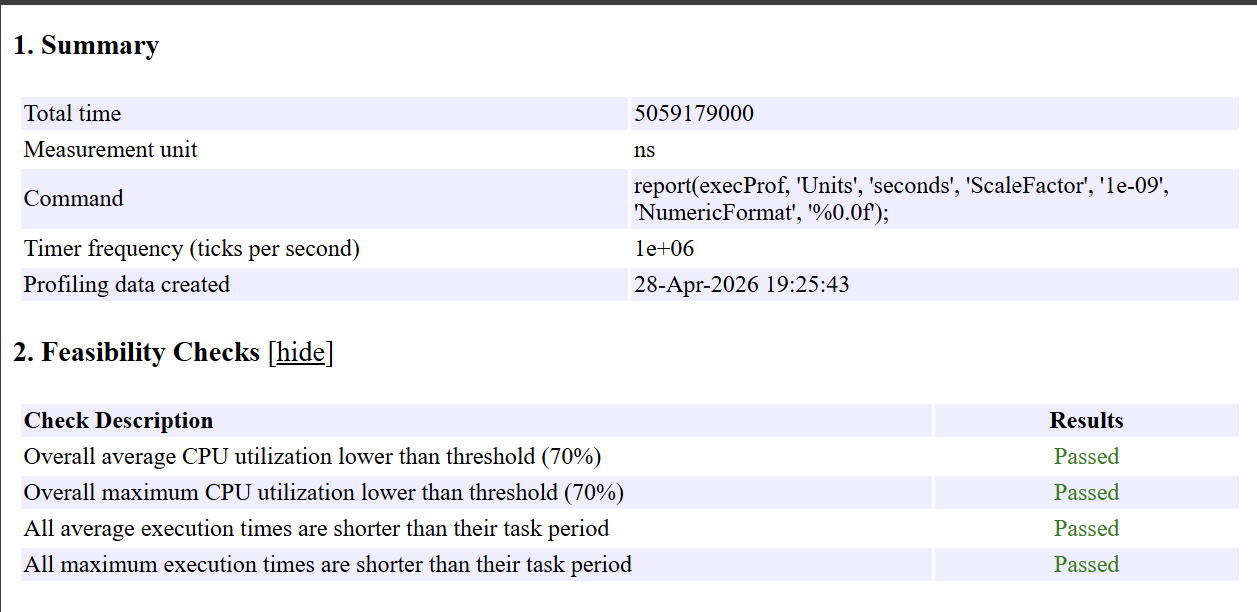

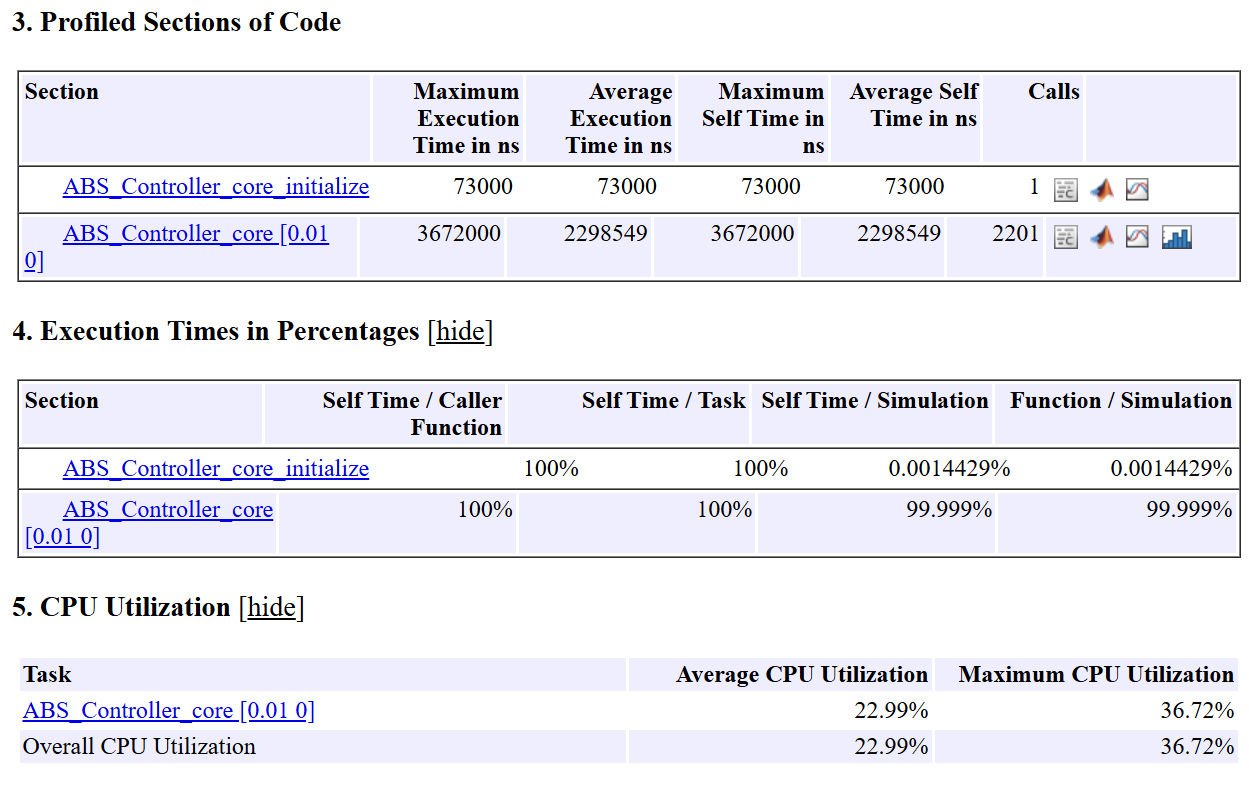

Execution profiling summary showing timing, feasibility checks, and CPU utilization of the ABS controller during PIL execution.

**Code Timing and Execution Analysis Conclusion**

- Execution profiling was performed using **Processor-in-the-Loop (PIL)** to evaluate real-time performance of the generated code 

- The **average execution time** of the controller task was approximately **2.30 ms**

- The **maximum execution time (worst-case)** was observed to be **3.67 ms**

- The controller operates with a **sampling time of 10 ms**, and both execution times are well within this limit 

- The **average CPU utilization** was measured as **22.99%**

- The **maximum CPU utilization** reached **36.72%**, which is below the specified threshold of 70% 

- All feasibility checks related to execution time and CPU utilization were successfully **passed**

- These results confirm that the controller meets **real-time execution requirements** and can run without missing deadlines on the target processor

**Code Stack Analysis ( Memory Usage Profiling )**

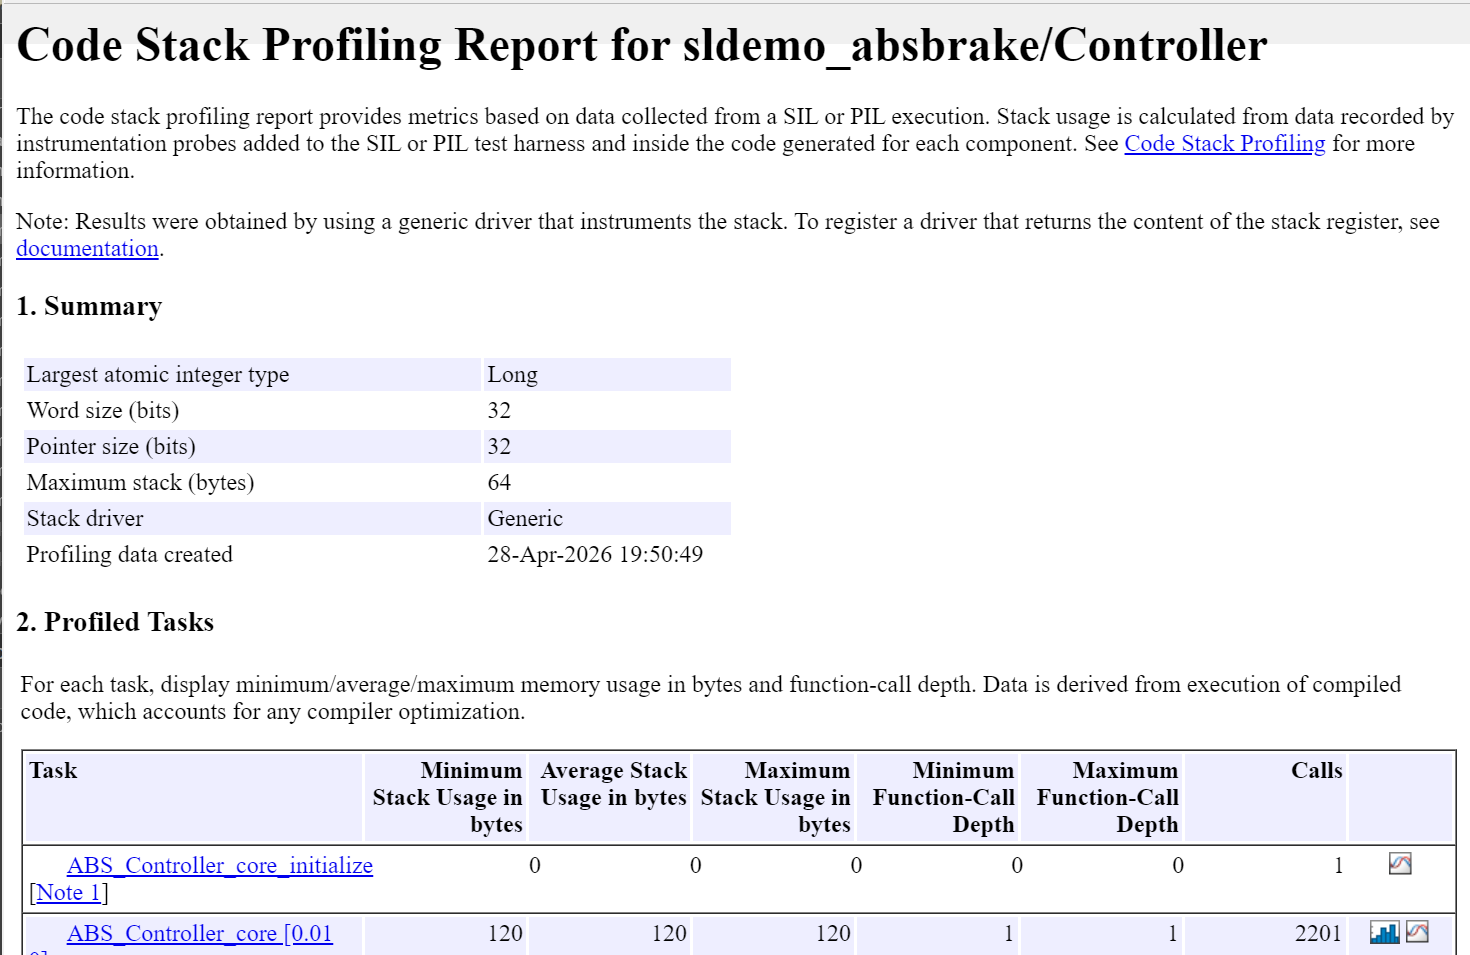

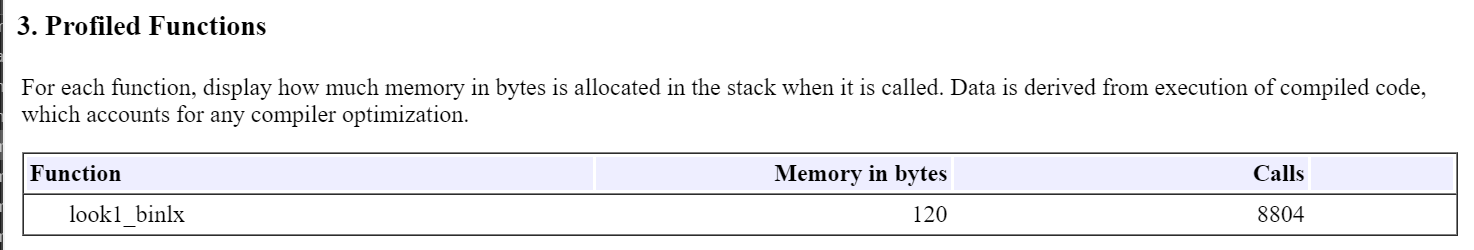

Stack memory profiling results showing task-level memory usage and function call characteristics during PIL execution.

The table presents the stack memory usage of the generated embedded code during execution. The minimum, average, and maximum stack usage indicate how much memory is allocated on the stack for each task, showing consistency in memory consumption. The function-call depth represents the level of nested function calls, where a value of 1 indicates a simple, non-recursive structure. The number of calls reflects how frequently each function is executed during simulation. These metrics confirm that the controller has low and stable memory usage, making it suitable for real-time embedded implementation.

- Stack profiling was performed during **PIL execution** to evaluate memory usage 

- The **maximum stack usage** was **120 bytes**, with consistent values across execution 

- The **function call depth** was **1**, indicating a simple and safe call structure 

- No stack overflow or abnormal memory behavior was observed 

- These results confirm **efficient and stable memory usage**, suitable for embedded deployment

**Code Coverage Analysis** 

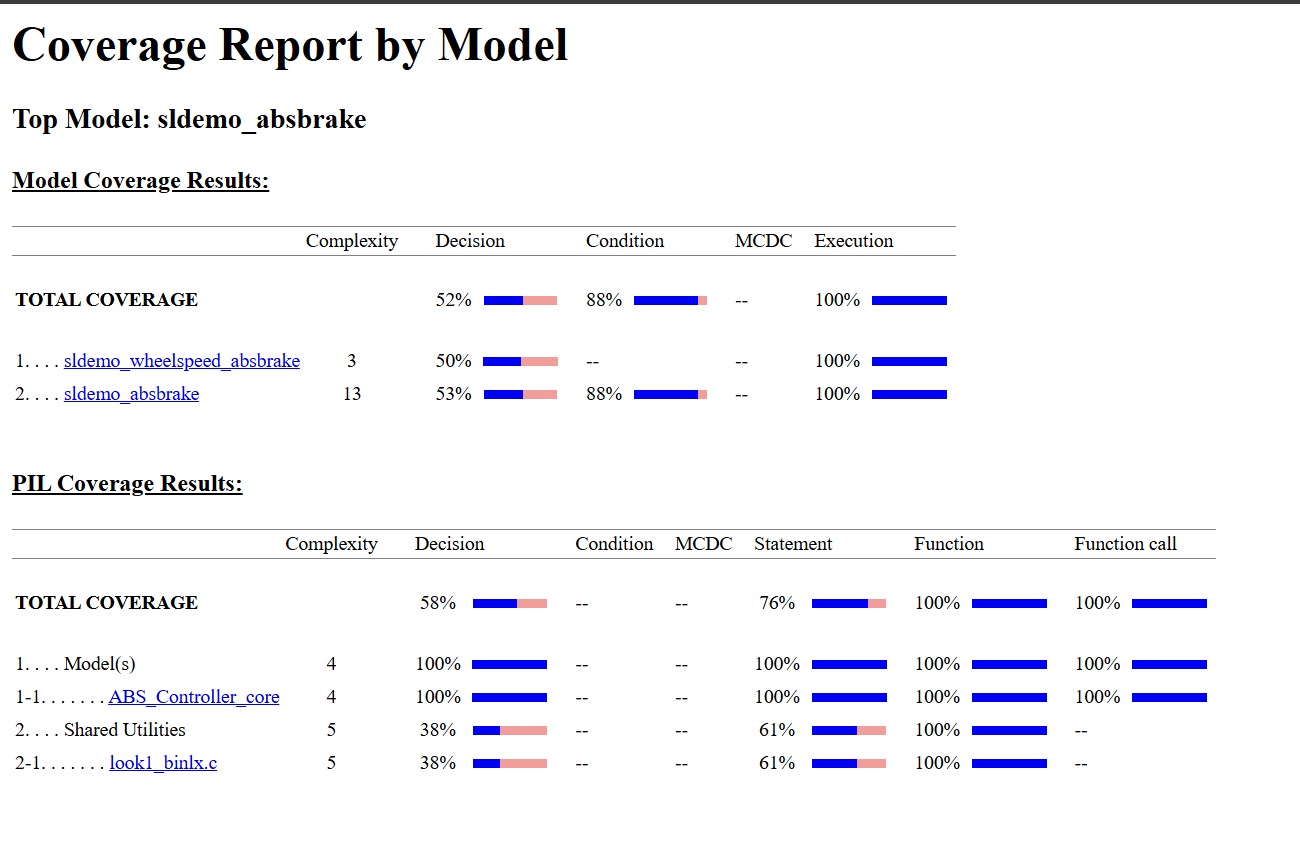

The generated embedded controller code achieved 100% decision, statement, and function coverage during PIL execution, indicating that all logical paths and conditions in the controller were successfully exercised.

At the system level, the model achieved 53% decision coverage and 88% condition coverage, with 100% execution coverage. This indicates that all model components were executed, though some decision branches remain partially untested.

Lower coverage in helper functions (such as lookup tables) is expected, as not all input conditions are exercised during simulation.

Table: Code coverage results indicating completeness of controller testing and validation of model execution.

**Static Code Analysis**

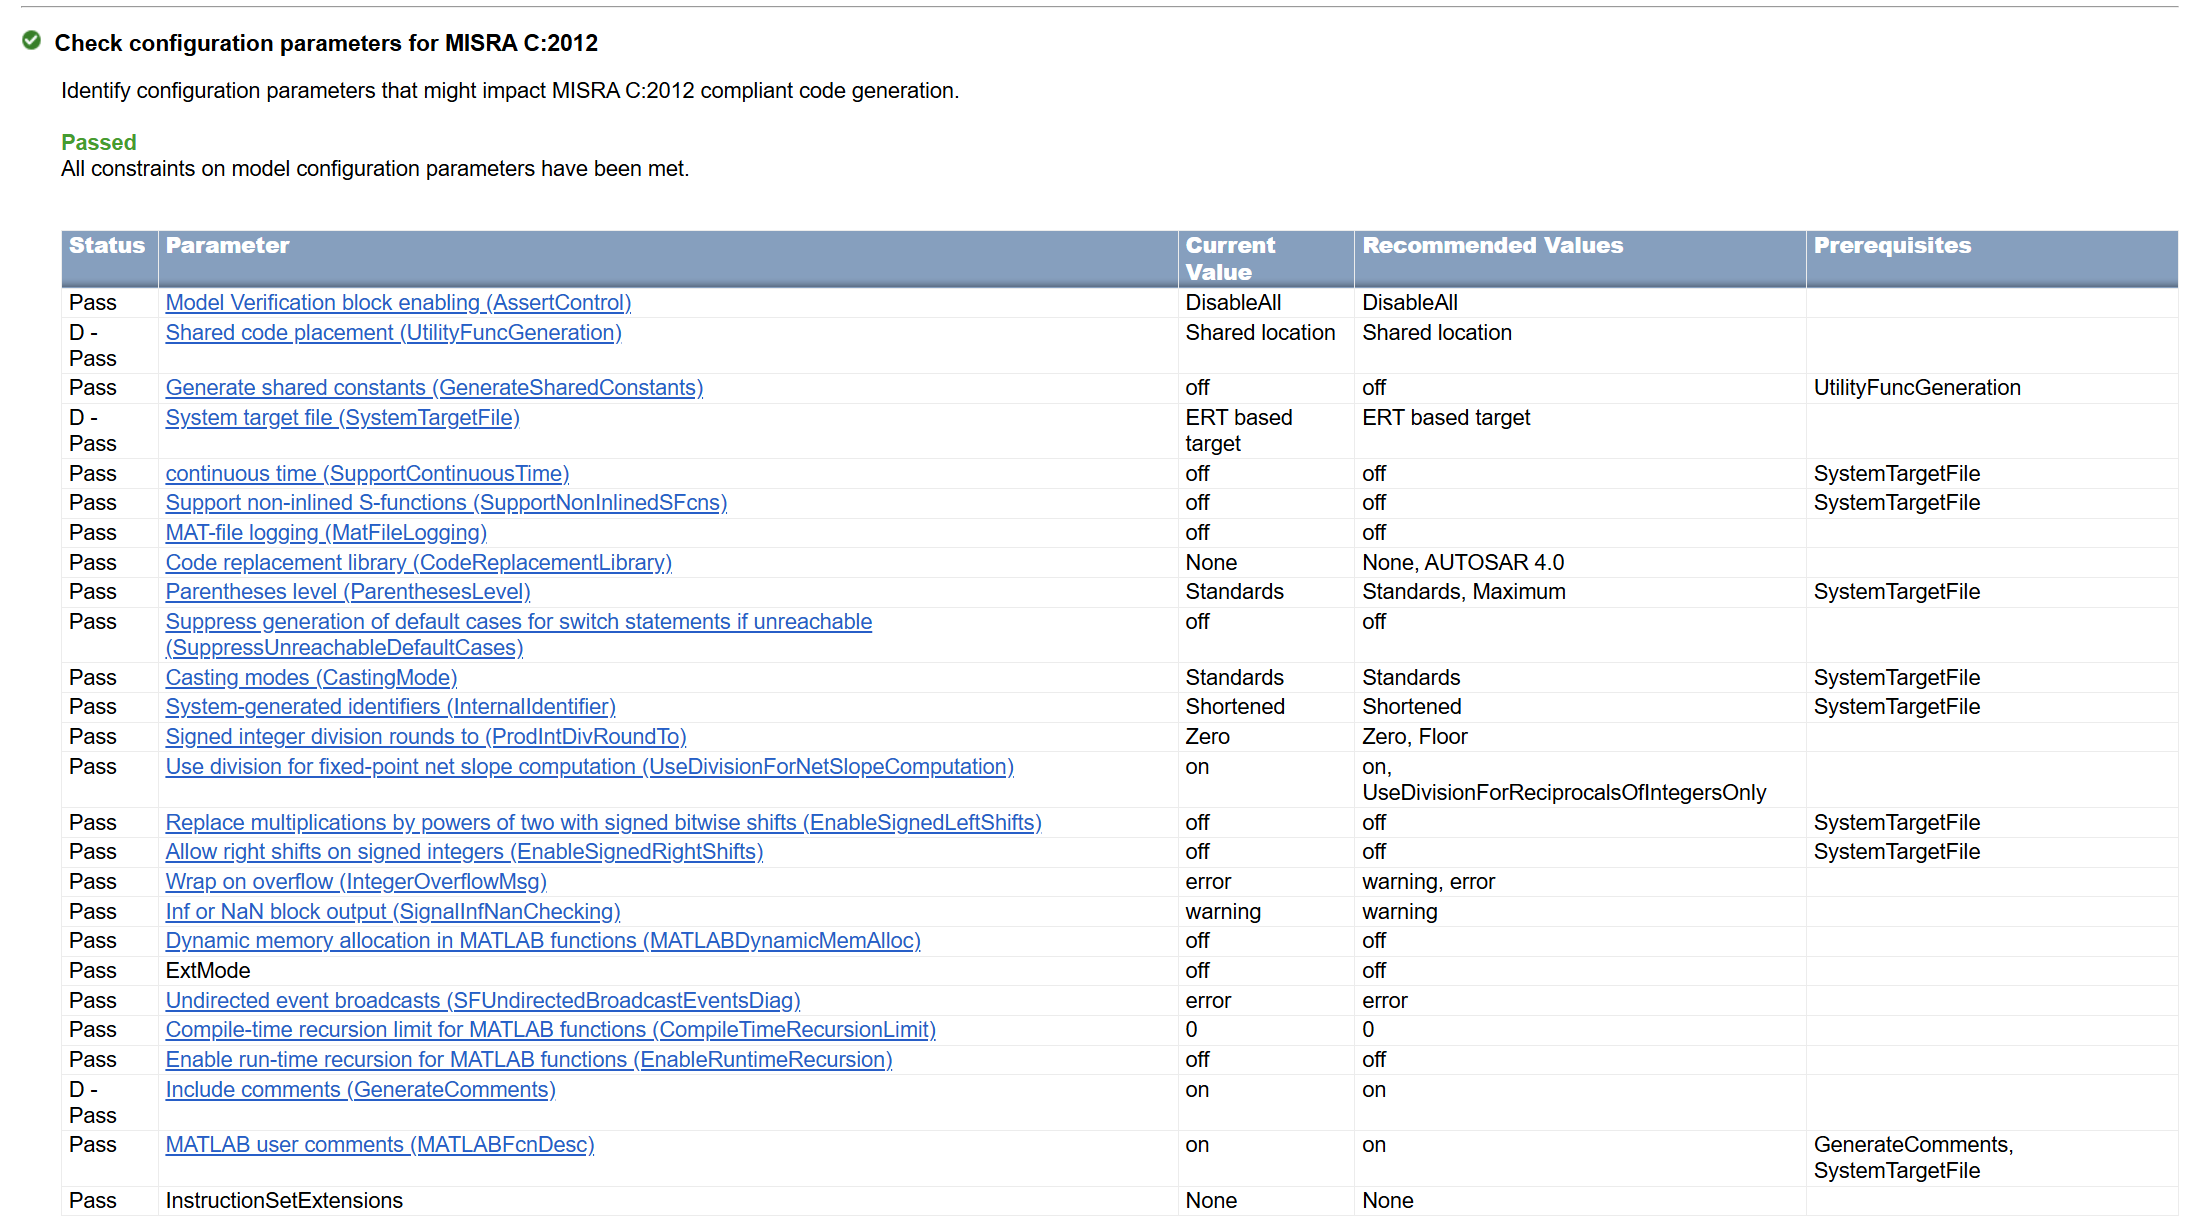

The generated code configuration was verified against MISRA C:2012 guidelines using Model Advisor checks. All required configuration constraints were successfully satisfied, indicating compliance with industry-standard coding practices for safety-critical systems.

Most parameters passed the compliance checks, with a few acceptable deviations (D-) observed. These deviations do not impact functional correctness and are permitted within the MISRA compliance framework.

Overall, the results confirm that the generated code adheres to MISRA C standards and is suitable for deployment in automotive embedded systems.

## **7. MIL, PIL Execution and Comparison Numerically**

The ABS controller was validated using both Model-in-the-Loop (MIL) and Processor-in-the-Loop (PIL) simulations to ensure correctness and deployability of the generated embedded code.

In the MIL phase, the controller was executed within the Simulink environment using floating-point precision, serving as the reference (golden model). A set of baseline tests was performed across three primary road conditions: Dry (μ = 0.80), Wet (μ = 0.50), and Ice (μ = 0.15). Key performance metrics such as wheel slip ratio, vehicle speed, and stopping distance were analyzed to evaluate controller behavior.

Subsequently, in the PIL phase, the generated C code was executed on an Arm Cortex-M7 Fast Model Emulator. This enabled verification of the controller under target-like execution conditions, including processor-level timing and numerical behavior.

A comprehensive parameter sweep consisting of 28 test cases was conducted across varying conditions such as initial speed, vehicle mass, braking force, tire radius, and slip targets. For each test case, both MIL and PIL simulations were executed, and results were compared.

**The controller performance was evaluated based on the following criteria:**

1. Slip Regulation: The maximum wheel slip should remain within a tolerance band of the target slip value.

2. Stopping Distance Improvement: The ABS-enabled system should achieve at least a 3% reduction in stopping distance compared to ABS disabled.

3. Numerical Equivalence: The stopping distances obtained from MIL and PIL simulations should match closely, indicating correctness of generated code.

The MIL simulations demonstrated effective slip regulation across all road conditions, maintaining wheel slip near the desired target values. The ABS controller consistently improved stopping distance compared to the non-ABS case, satisfying the required performance threshold.

The PIL simulations produced results that closely matched the MIL outputs. The stopping distances obtained from both environments showed negligible differences across all test cases. The absolute error between MIL and PIL results was observed to be near zero, confirming numerical equivalence.

Graphical comparisons of stopping distance and error plots further validated that the generated embedded code behaves identically to the high-level model. This confirms that no significant numerical errors, data type issues, or implementation mismatches were introduced during code generation.

The MIL and PIL comparison confirms that the generated embedded C code is functionally correct, numerically equivalent to the Simulink model, and suitable for deployment on the target Arm Cortex-M7 processor. The successful validation across multiple operating conditions demonstrates the robustness and reliability of the ABS controller implementation.

To execute comparative analysys between PIL and MIL , there needs to setup for PIL and virtual ARM Processor , if setup the same way , the paths to the Arm Emulator has to be setup in the following places 

**a) Press ctrl + e in the main simuling top model** 

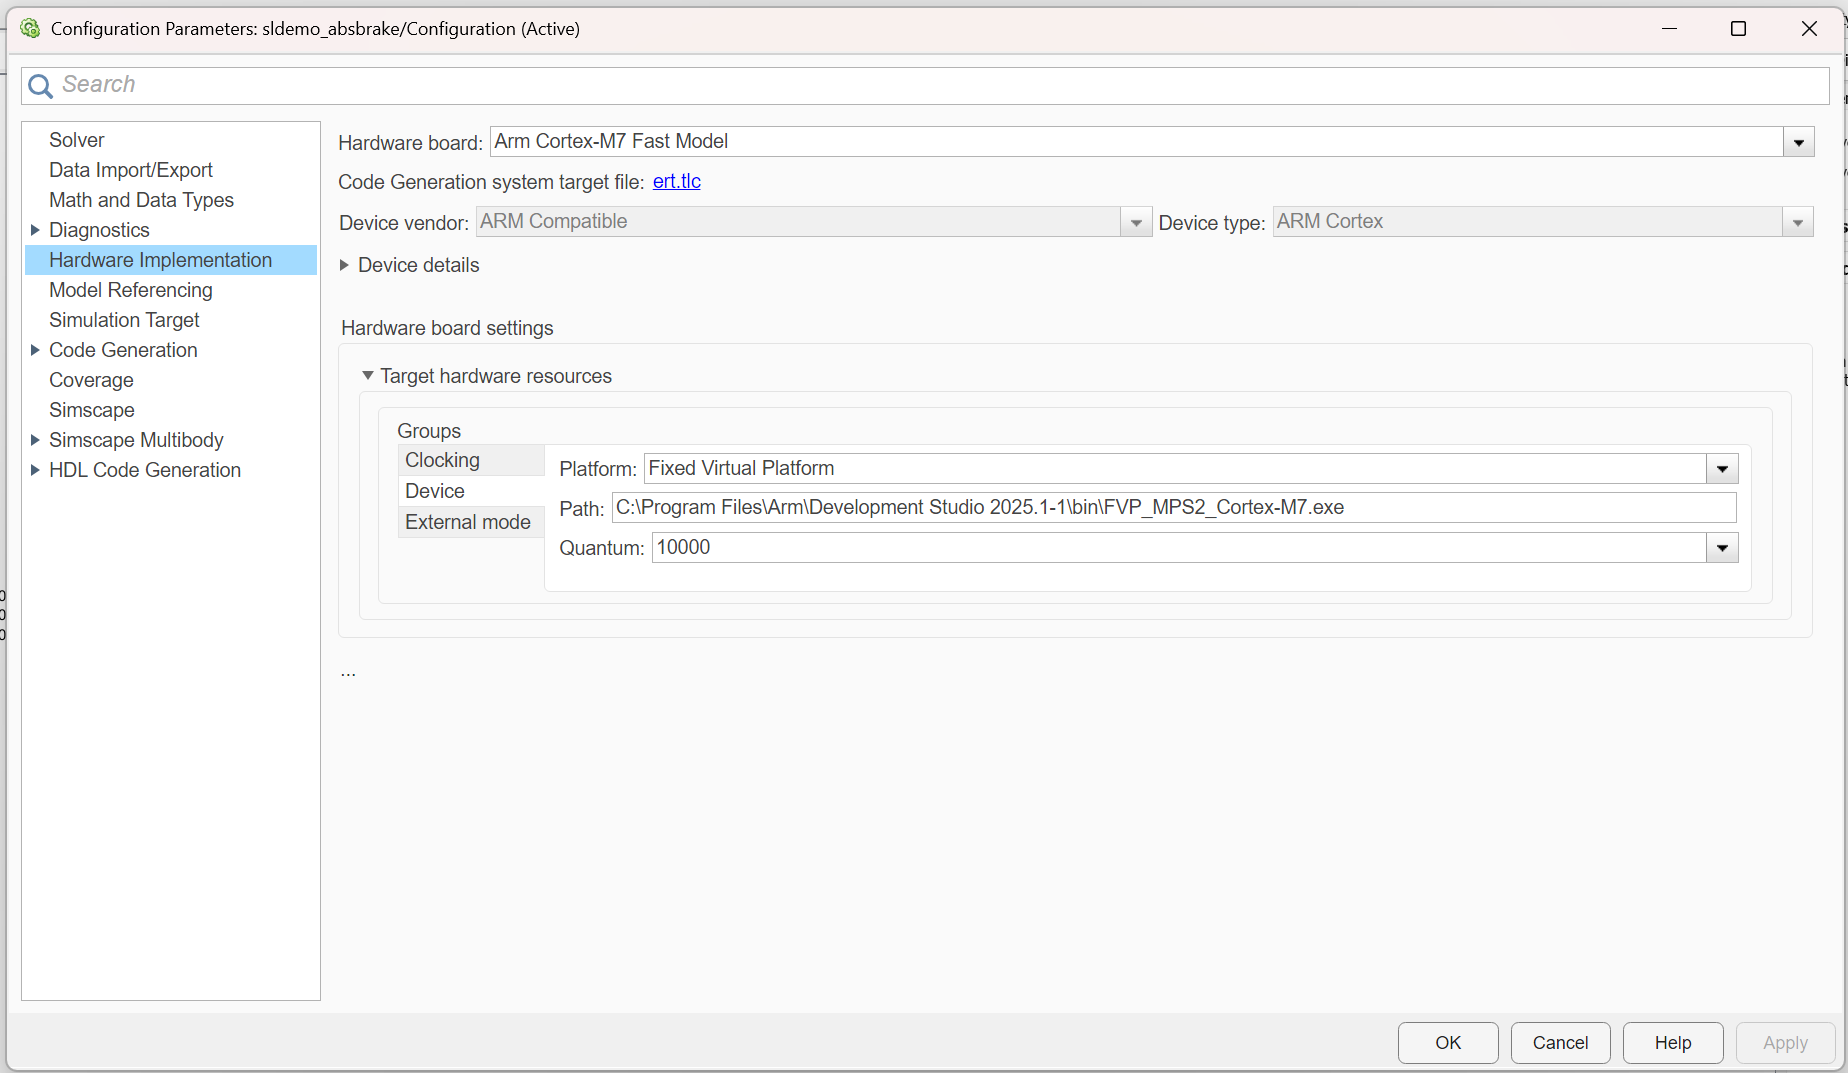

**b) Enter into the ABS_Controller_core block and perform the same procedure as above**

**c) If still not executing , then change the paths in every block (if necessary)** 

**d) Uncomment **`run_mil_pil_test_compare `**and Execute the respective code** 

  ABS MIL & PIL VERIFICATION CAMPAIGN
  Model : sldemo_absbrake
  Date  : 2026-04-30 14:29:35
  Output Directory : .\MIL_PIL_Results\

--- Phase A : 3-road core test (MIL Baseline) ---



[Dry] mu_peak=0.80  slipTgt=0.20  maxSlip=0.246  stopON=774.4 ft  stopOFF=815.5 ft  saves=5.0%  PASS


[Wet] mu_peak=0.50  slipTgt=0.15  maxSlip=0.233  stopON=1107.5 ft  stopOFF=1279.3 ft  saves=13.4%  PASS


[Ice] mu_peak=0.15  slipTgt=0.10  maxSlip=0.220  stopON=2013.2 ft  stopOFF=2106.4 ft  saves=4.4%  FAIL

--- Phase B : 35-case parameter sweep (MIL & PIL) ---

--- Executing MIL Sweep ---


[ 1/28] Dry_Nominal_88fps               maxSlip=0.25  stop=774.4 ft  saves=  5.0%  PASS


[ 2/28] Dry_HighSpeed_100fps            maxSlip=0.25  stop=973.1 ft  saves=  6.1%  PASS


[ 3/28] Dry_Heavy_Mass60                maxSlip=0.25  stop=833.6 ft  saves=  6.4%  PASS


[ 4/28] Dry_Light_Mass40                maxSlip=0.24  stop=728.5 ft  saves=  4.6%  PASS


[ 5/28] Dry_LowBrake_PB1200             maxSlip=0.25  stop=805.7 ft  saves=  8.1%  PASS


[ 6/28] Dry_HighBrake_PB1700            maxSlip=0.25  stop=749.1 ft  saves=  3.7%  PASS


[ 7/28] Dry_SlipTgt_0p15                maxSlip=0.25  stop=774.4 ft  saves=  5.0%  PASS


[ 8/28] Dry_SlipTgt_0p25                maxSlip=0.25  stop=774.4 ft  saves=  5.0%  PASS


[ 9/28] Dry_SmallTire_Rr1p15            maxSlip=0.24  stop=759.9 ft  saves=  5.2%  PASS


[10/28] Dry_TinyTire_Rr1p05             maxSlip=0.24  stop=743.4 ft  saves=  5.8%  PASS


[11/28] Dry_Combined_HeavyFast          maxSlip=0.25  stop=976.3 ft  saves=  3.7%  PASS


[12/28] Wet_Nominal                     maxSlip=0.23  stop=1107.5 ft  saves= 13.4%  PASS


[13/28] Wet_HighSpeed_100               maxSlip=0.23  stop=1397.8 ft  saves= 15.8%  PASS


[14/28] Wet_Light_Mass40                maxSlip=0.23  stop=1068.4 ft  saves= 11.5%  PASS


[15/28] Wet_SlipTgt_0p12                maxSlip=0.23  stop=1107.5 ft  saves= 13.4%  PASS


[16/28] Wet_SlipTgt_0p18                maxSlip=0.23  stop=1107.5 ft  saves= 13.4%  PASS


[17/28] Wet_HighBrake_PB1700            maxSlip=0.23  stop=1084.1 ft  saves= 10.9%  PASS


[18/28] Ice_Nominal                     maxSlip=0.22  stop=2122.4 ft  saves=  5.0%  PASS


[19/28] Ice_Light_Mass40                maxSlip=0.22  stop=2012.0 ft  saves=  4.7%  PASS


[20/28] Ice_SlipTgt_0p12                maxSlip=0.22  stop=2122.4 ft  saves=  5.0%  PASS


[21/28] Ice_Combined_HeavyFast          maxSlip=0.22  stop=2553.1 ft  saves=  5.7%  PASS


[22/28] Snow_mu0p30                     maxSlip=0.22  stop=1482.1 ft  saves=  8.4%  PASS


[23/28] Snow_mu0p30_HighSpd             maxSlip=0.22  stop=1715.6 ft  saves=  8.7%  PASS


[24/28] Snow_mu0p35_Mid                 maxSlip=0.23  stop=1330.9 ft  saves=  8.5%  PASS


[25/28] Snow_mu0p35_HighSpd             maxSlip=0.23  stop=1544.0 ft  saves=  9.0%  PASS


[26/28] Dry_HighSpeed_110               maxSlip=0.25  stop=1139.8 ft  saves=  6.1%  PASS


[27/28] Ice_LowSpeed_50                 maxSlip=0.16  stop=957.3 ft  saves= -1.8%  FAIL


[28/28] Gravel_mu0p40                   maxSlip=0.09  stop=1354.0 ft  saves= -9.4%  FAIL
--> MIL Sweep complete | 26 / 28 PASS (92.9%)

--- Executing PIL Sweep ---
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### Creating 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' ...
### Building 'rtwshared': "C:\PROGRA

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[ 1/28] Dry_Nominal_88fps               stop=774.4 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[ 2/28] Dry_HighSpeed_100fps            stop=973.1 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[ 3/28] Dry_Heavy_Mass60                stop=833.6 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[ 4/28] Dry_Light_Mass40                stop=728.5 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[ 5/28] Dry_LowBrake_PB1200             stop=805.7 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[ 6/28] Dry_HighBrake_PB1700            stop=749.1 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[ 7/28] Dry_SlipTgt_0p15                stop=774.4 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[ 8/28] Dry_SlipTgt_0p25                stop=774.4 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[ 9/28] Dry_SmallTire_Rr1p15            stop=759.9 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[10/28] Dry_TinyTire_Rr1p05             stop=743.4 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[11/28] Dry_Combined_HeavyFast          stop=976.3 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[12/28] Wet_Nominal                     stop=1107.5 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[13/28] Wet_HighSpeed_100               stop=1397.8 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[14/28] Wet_Light_Mass40                stop=1068.4 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[15/28] Wet_SlipTgt_0p12                stop=1107.5 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[16/28] Wet_SlipTgt_0p18                stop=1107.5 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[17/28] Wet_HighBrake_PB1700            stop=1084.1 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[18/28] Ice_Nominal                     stop=2122.4 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[19/28] Ice_Light_Mass40                stop=2012.0 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[20/28] Ice_SlipTgt_0p12                stop=2122.4 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[21/28] Ice_Combined_HeavyFast          stop=2553.1 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[22/28] Snow_mu0p30                     stop=1482.1 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[23/28] Snow_mu0p30_HighSpd             stop=1715.6 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[24/28] Snow_mu0p35_Mid                 stop=1330.9 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[25/28] Snow_mu0p35_HighSpd             stop=1544.0 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[26/28] Dry_HighSpeed_110               stop=1139.8 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[27/28] Ice_LowSpeed_50                 stop=957.3 ft (PIL)
### Searching for referenced models in model 'sldemo_absbrake'.
### Total of 1 models to build.
### Starting serial code generation build.
### Checking status of model reference code generation target for model 'ABS_Controller_core'.
### Model reference code generation target 'ABS_Controller_core.c' for model 'ABS_Controller_core' must be compiled because this target has changed since the last build or has not been compiled.
### Starting build procedure for: ABS_Controller_core
### Generating code and artifacts to 'Model specific' folder structure
### Using toolchain: GNU Tools for ARM Embedded Processors
### 'C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\_sharedutils\instrumented\rtwshared.mk' is up to date.
### Building 'rtwshared': "C:\PROGRA~1\MATLAB\R2025b\bin\win64\gmake"  -f rtwshared.mk all
 
C:\Users\vipul\Documents\6th sem EL\simulink_

### Starting application: 'slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf'
### Downloading application...C:\Users\vipul\Documents\6th sem EL\simulink_automotive_pil\simulink_automotive\ModelingAnAntiLockBrakingSystemExample\slprj\ert\ABS_Controller_core\pil\ABS_Controller_core.elf
Simulation complete. Application will now be terminated safely.
### Completed code coverage analysis


[28/28] Gravel_mu0p40                   stop=1354.0 ft (PIL)

Both Sweeps complete in 1086.0 s

--- Phase C : Reporting ---



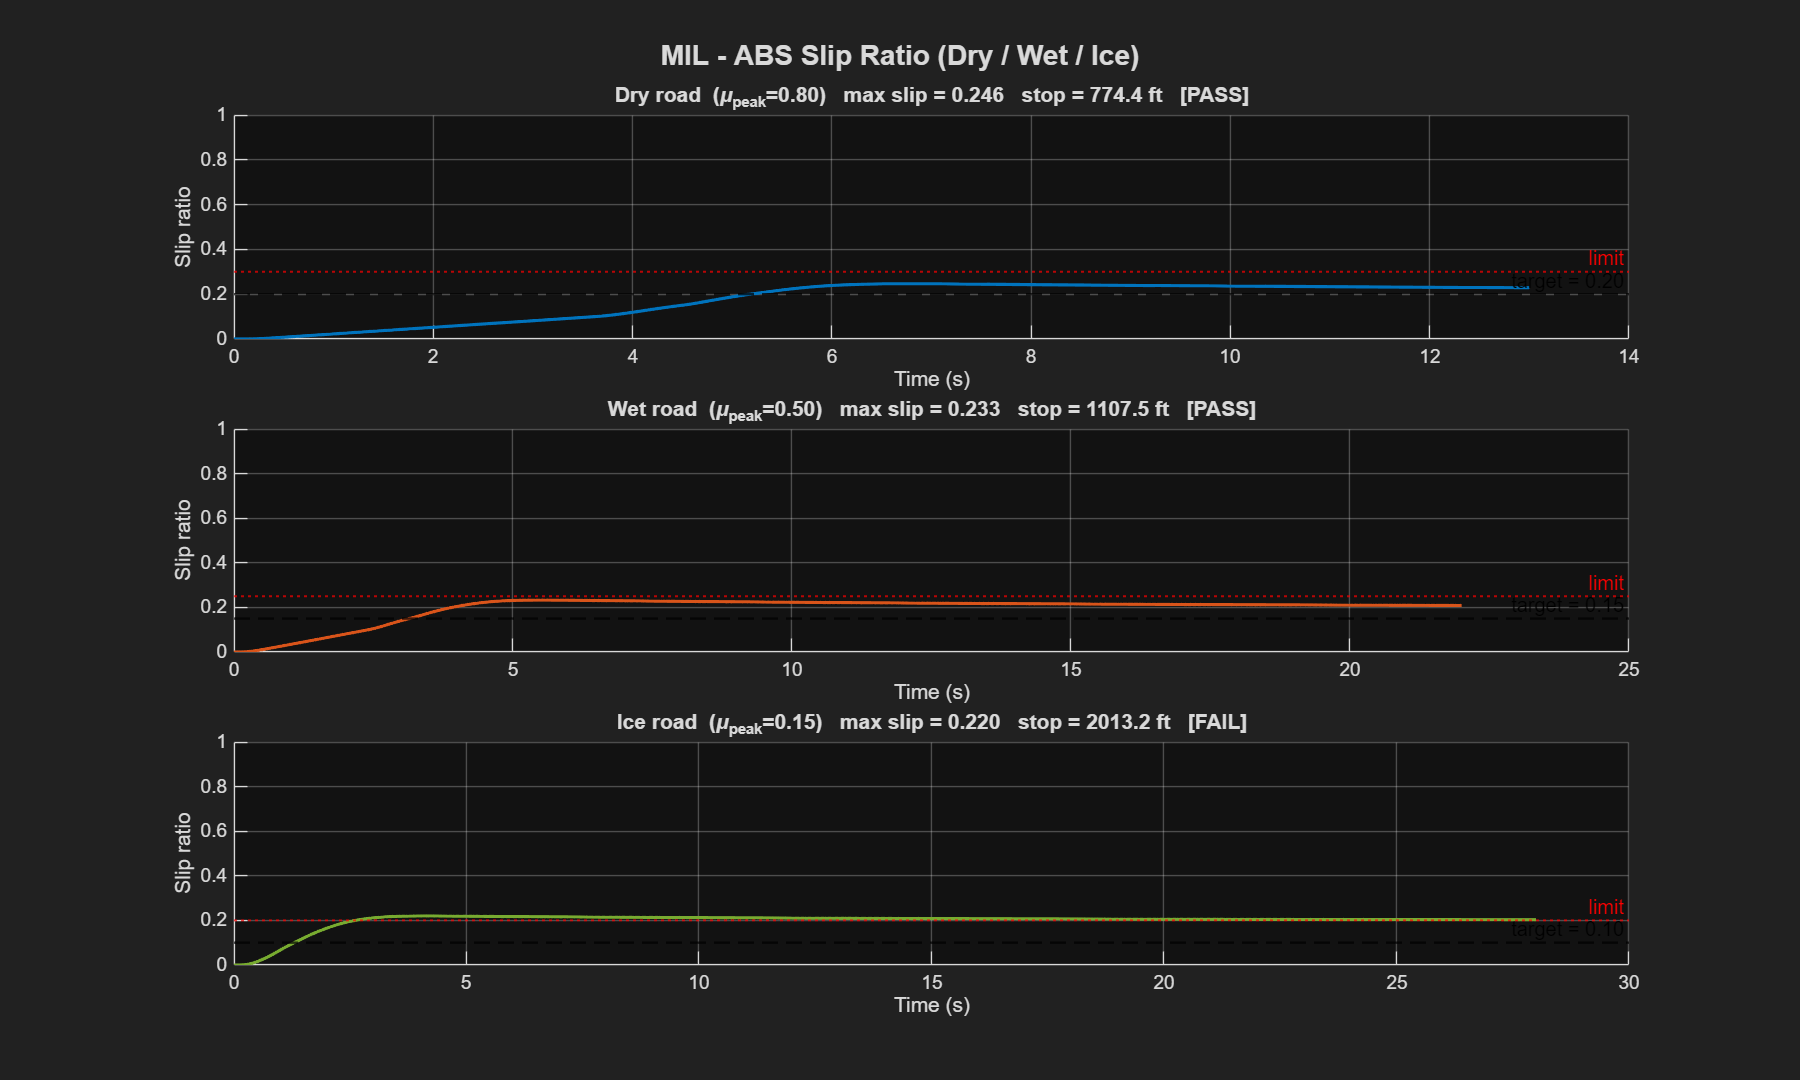

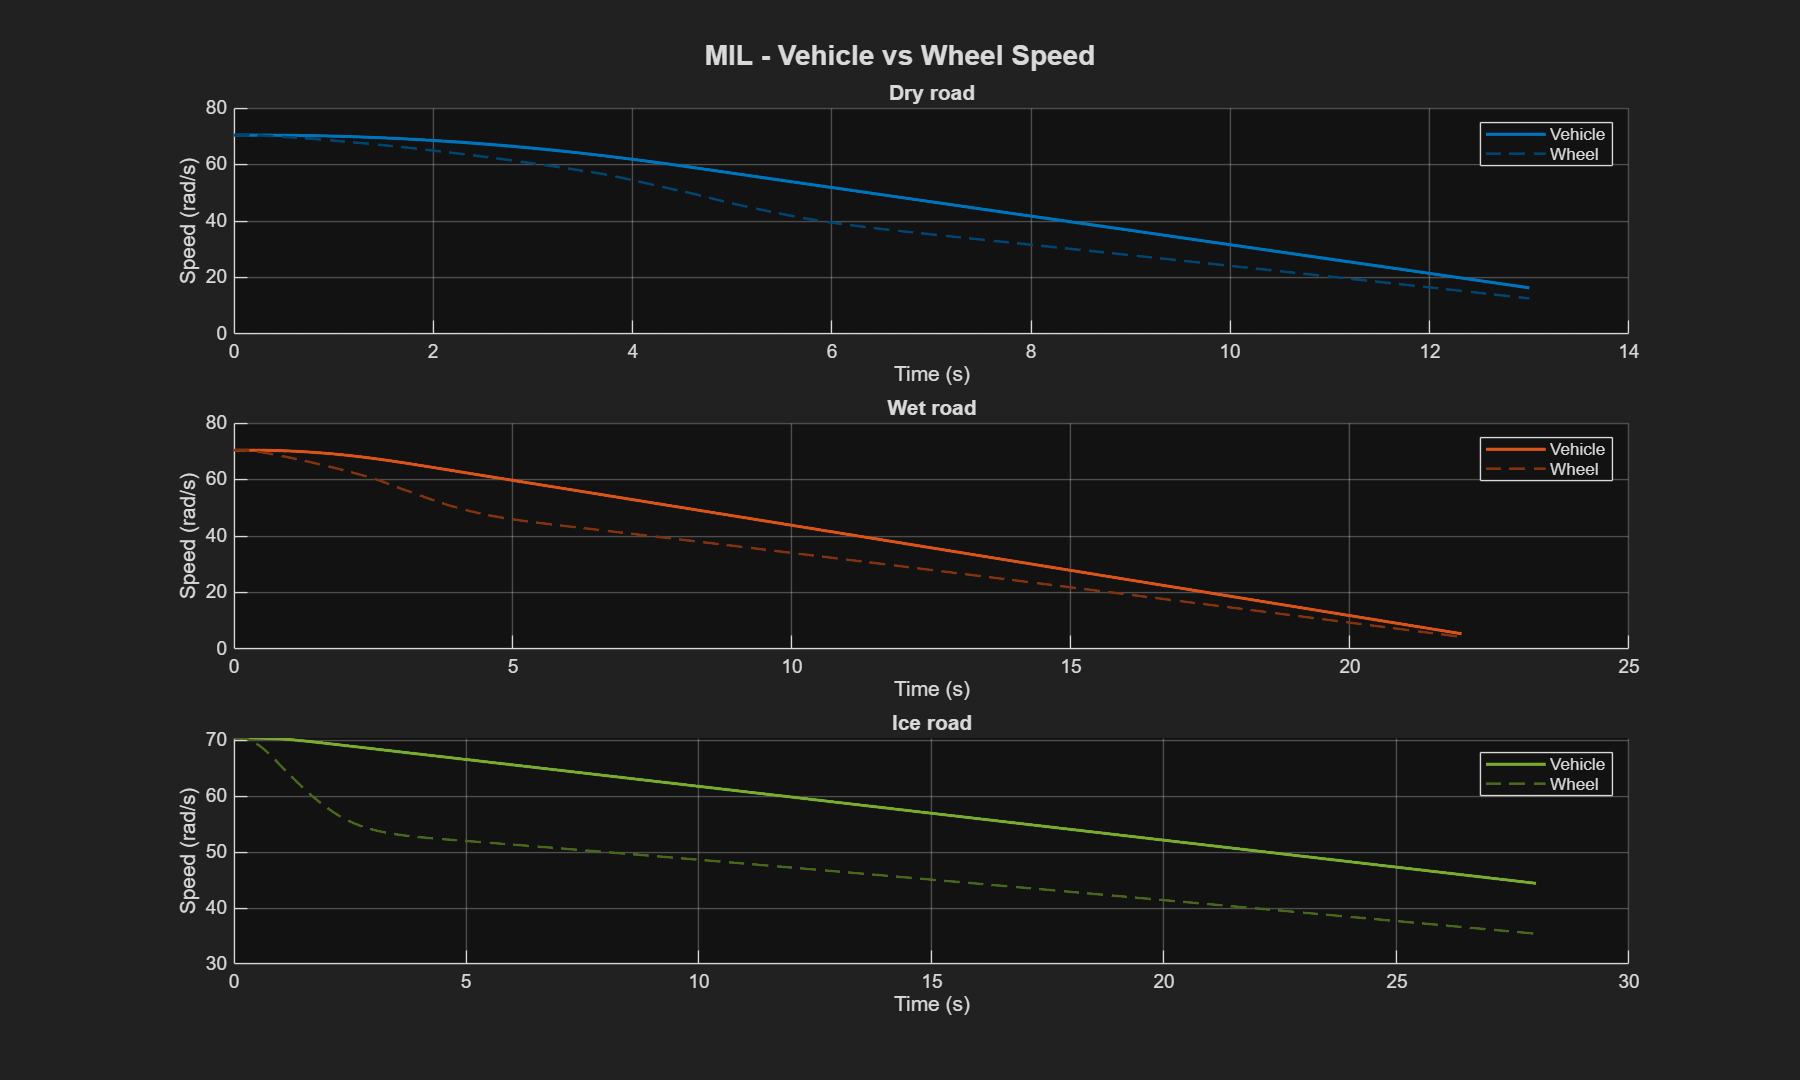

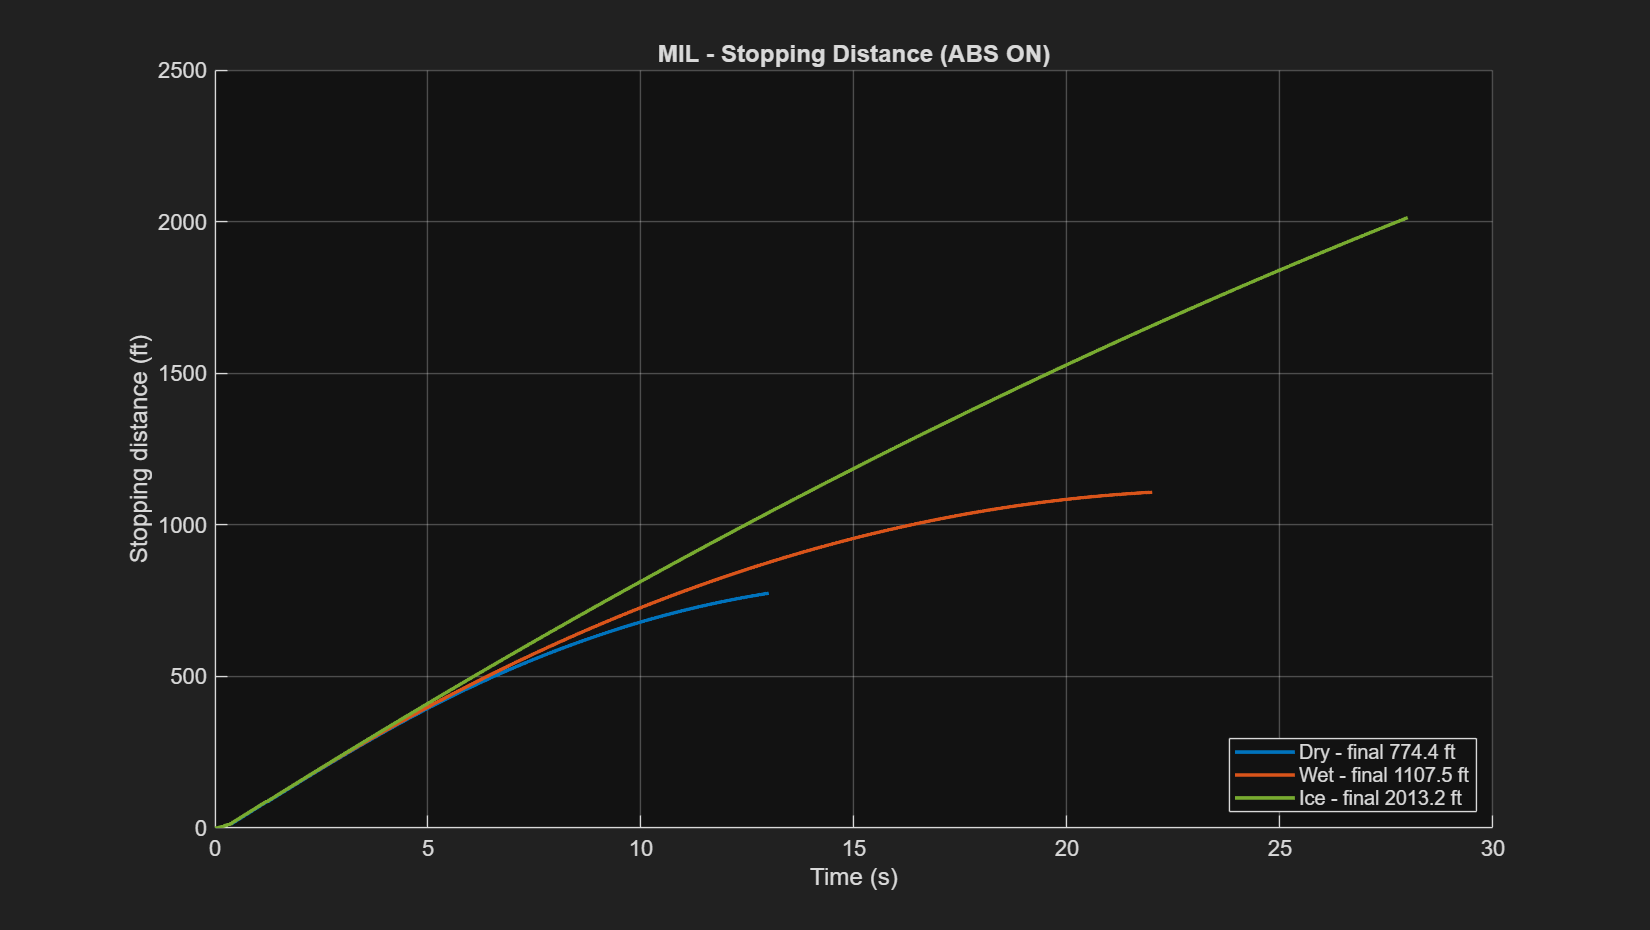

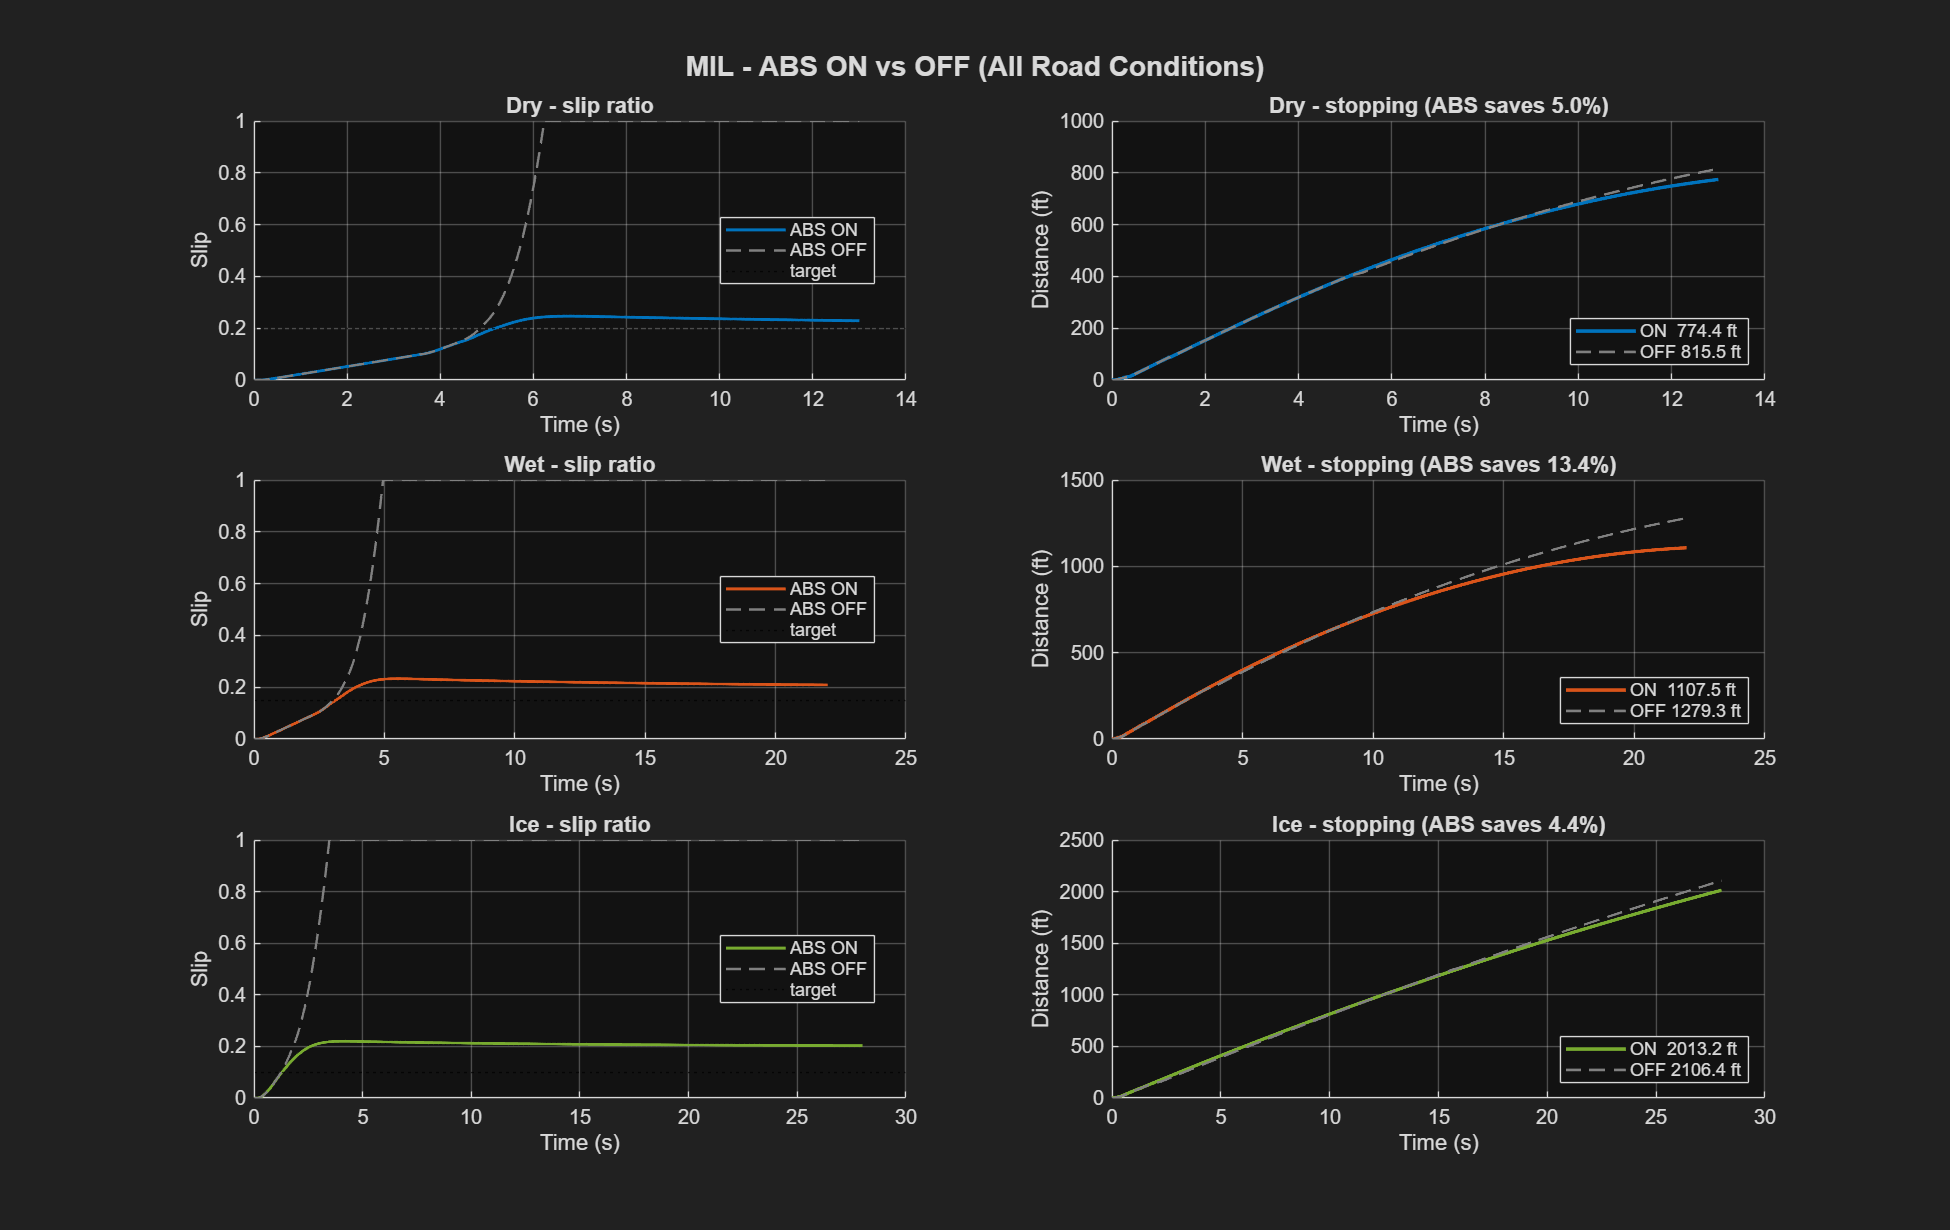

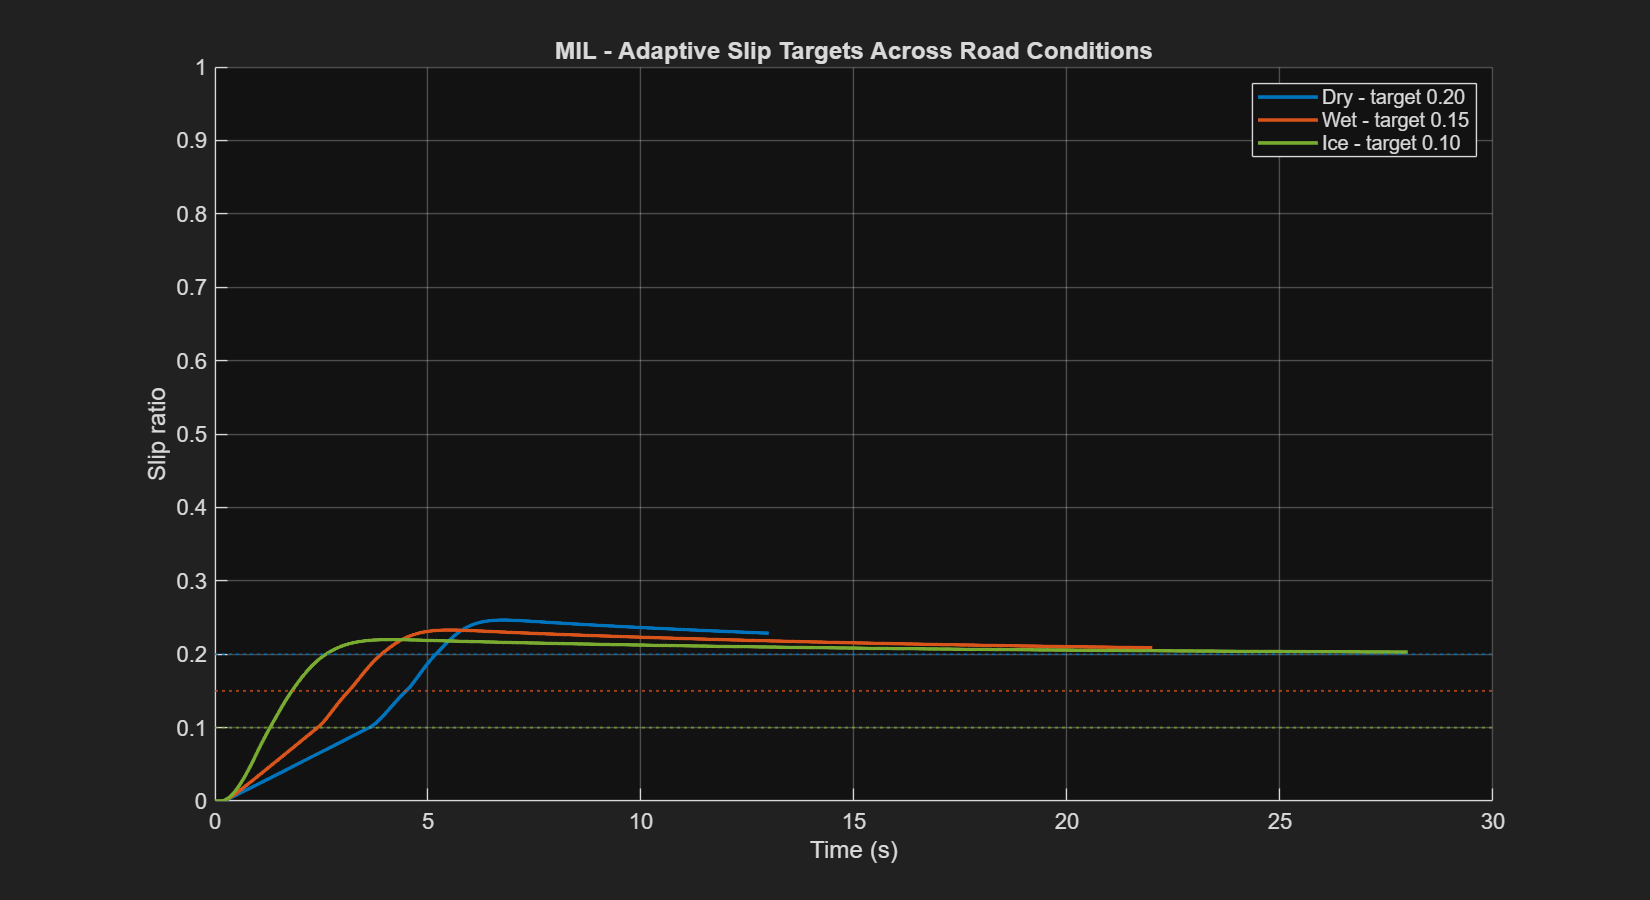

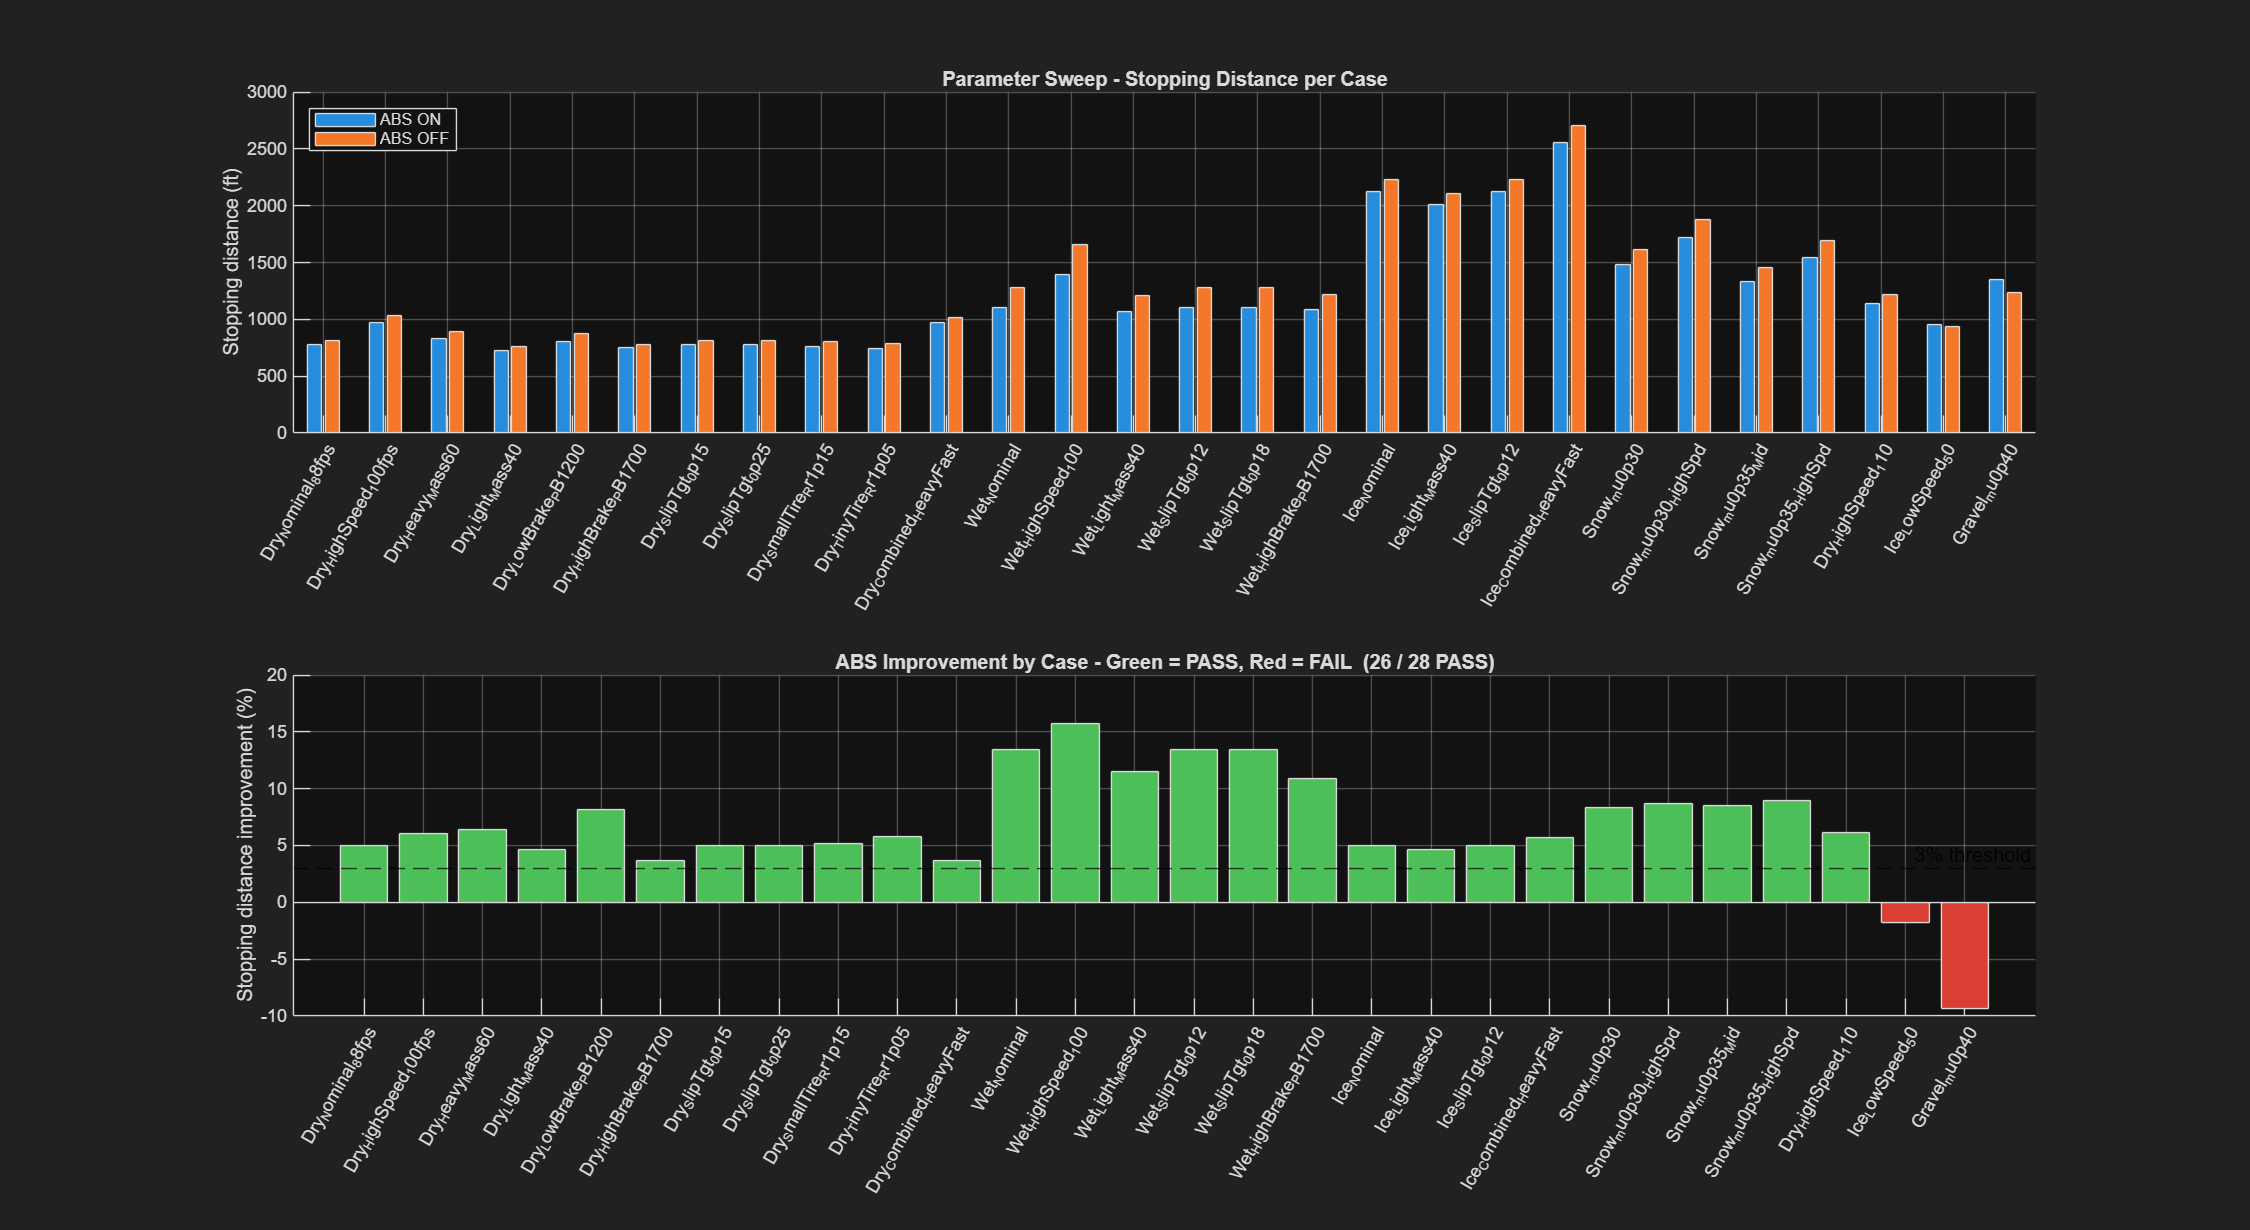

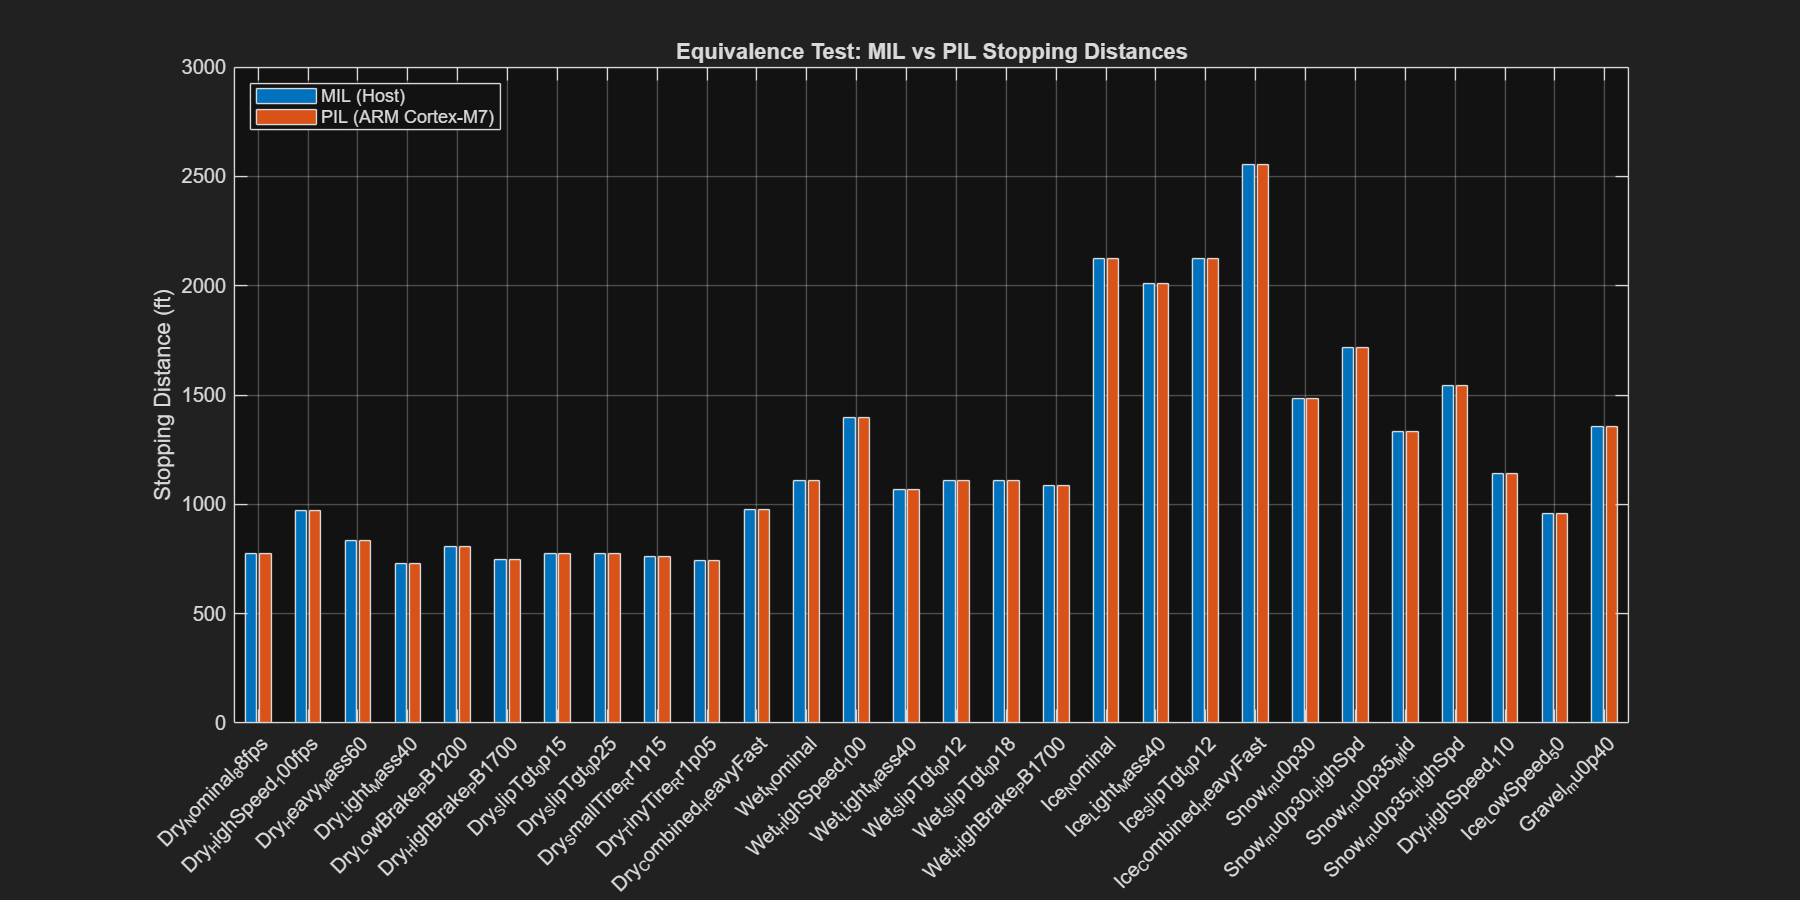

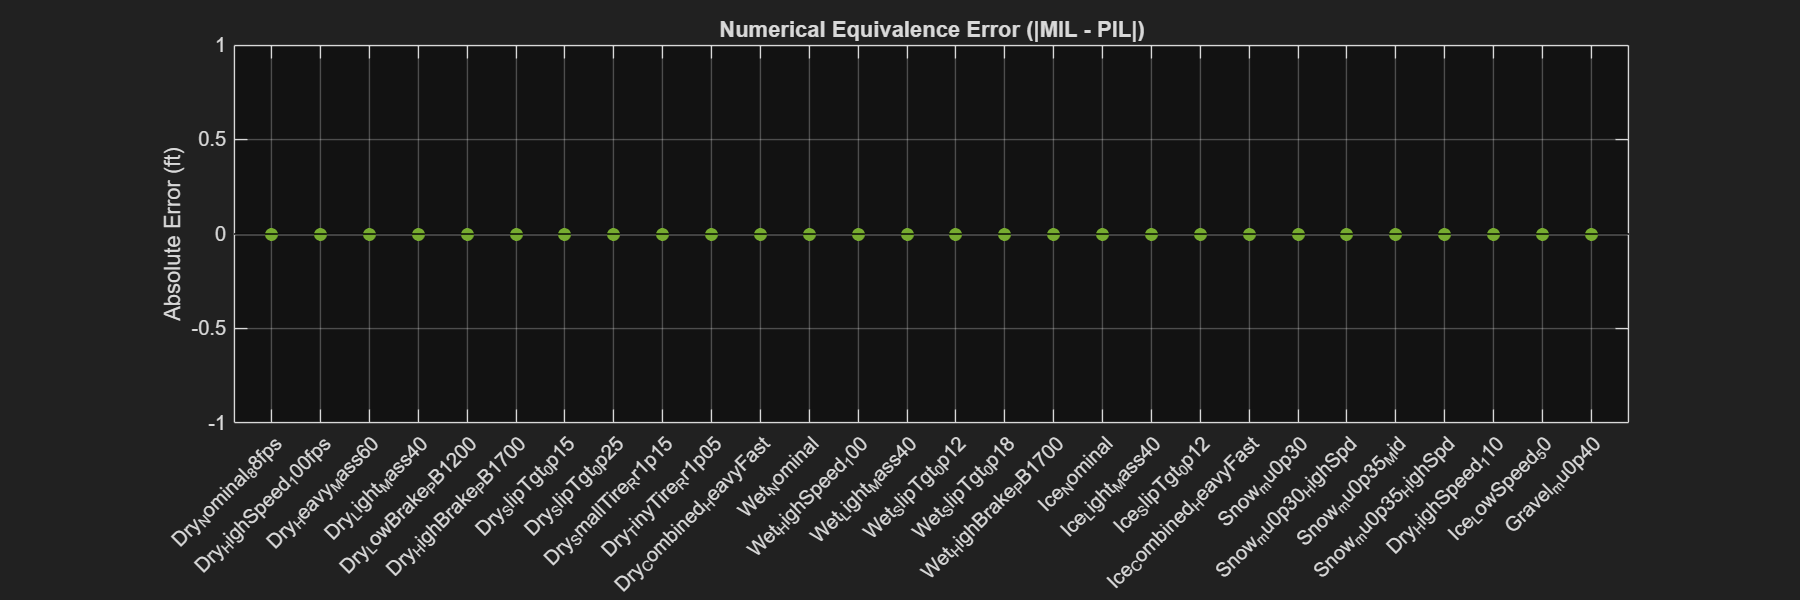

Artifacts saved to MIL_PIL_Results\:
  fig1_slip_ratio.png
  fig2_speed.png
  fig3_stopping_distance.png
  fig4_abs_on_vs_off.png
  fig5_adaptive_overlay.png
  fig6_sweep_summary.png
  fig7_mil_vs_pil_distance.png
  fig8_mil_vs_pil_error.png
  MIL_PIL_TestSuite_Results.csv
  MIL_PIL_TestSuite_Results.xlsx
  MIL_PIL_Report.txt

CAMPAIGN COMPLETE.
--- Phase D : Execution Profiling Metrics ---
No executionProfile found inside simOn. Check Simulink Code Generation settings.

--- Stack Profiling Metrics ---
No stackProfile found. Check if stack profiling is enabled in settings.


%Code to compare MIL annd PIL values numerically 
%run_mil_pil_test_compare

## **8. MIL, PIL Execution and Comparison Results **

**a) Phase A - Slip Ratio**

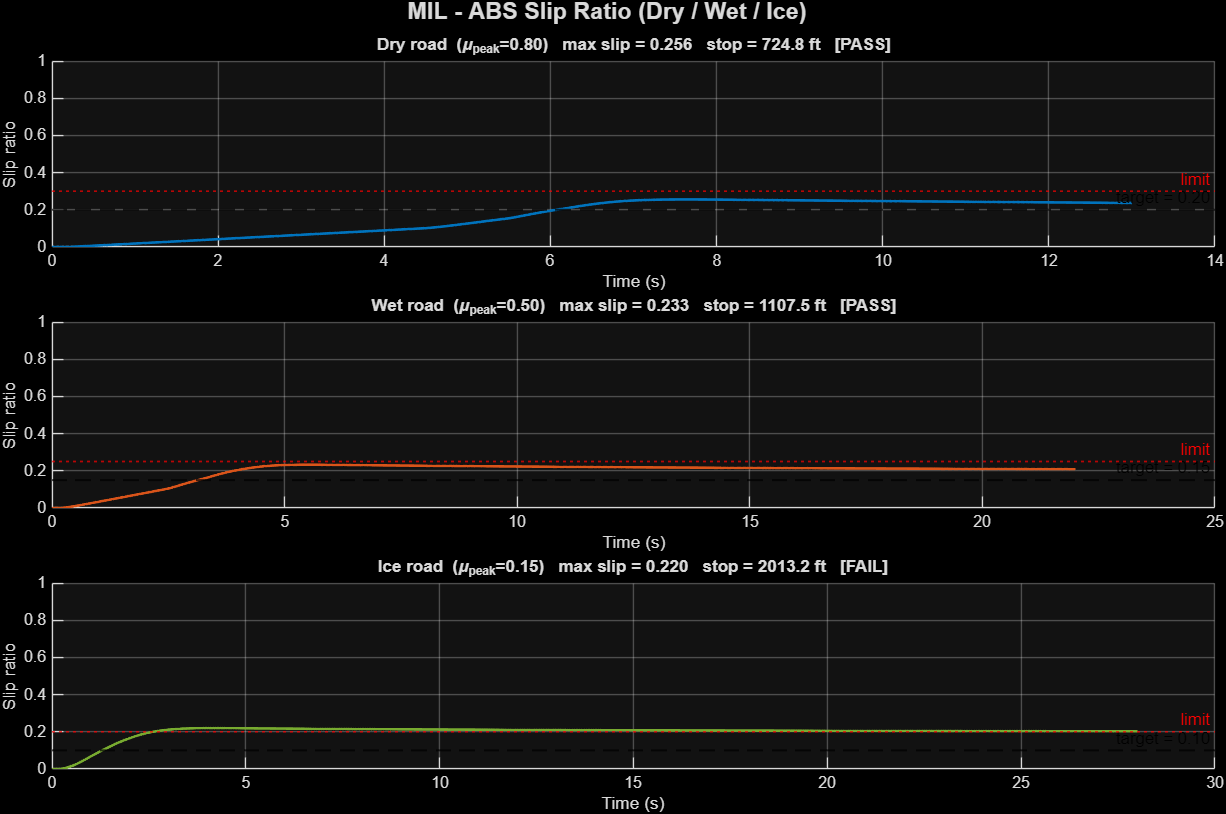

Figure: Slip ratio response of the ABS controller under Dry, Wet, and Ice conditions.

The controller regulates wheel slip towards the target values (0.20 for dry, 0.15 for wet, and 0.10 for ice), shown by the dashed line (black). The dotted line (red) represents the upper limit (target + 0.10), which defines the acceptable slip range. The slip remains close to the target and within the limit for dry and wet conditions, indicating stable and effective braking. Under ice conditions, the slip approaches the limit due to reduced friction, highlighting the challenges of control in low-traction environments..

**b) Phase A - Speeds Comp **

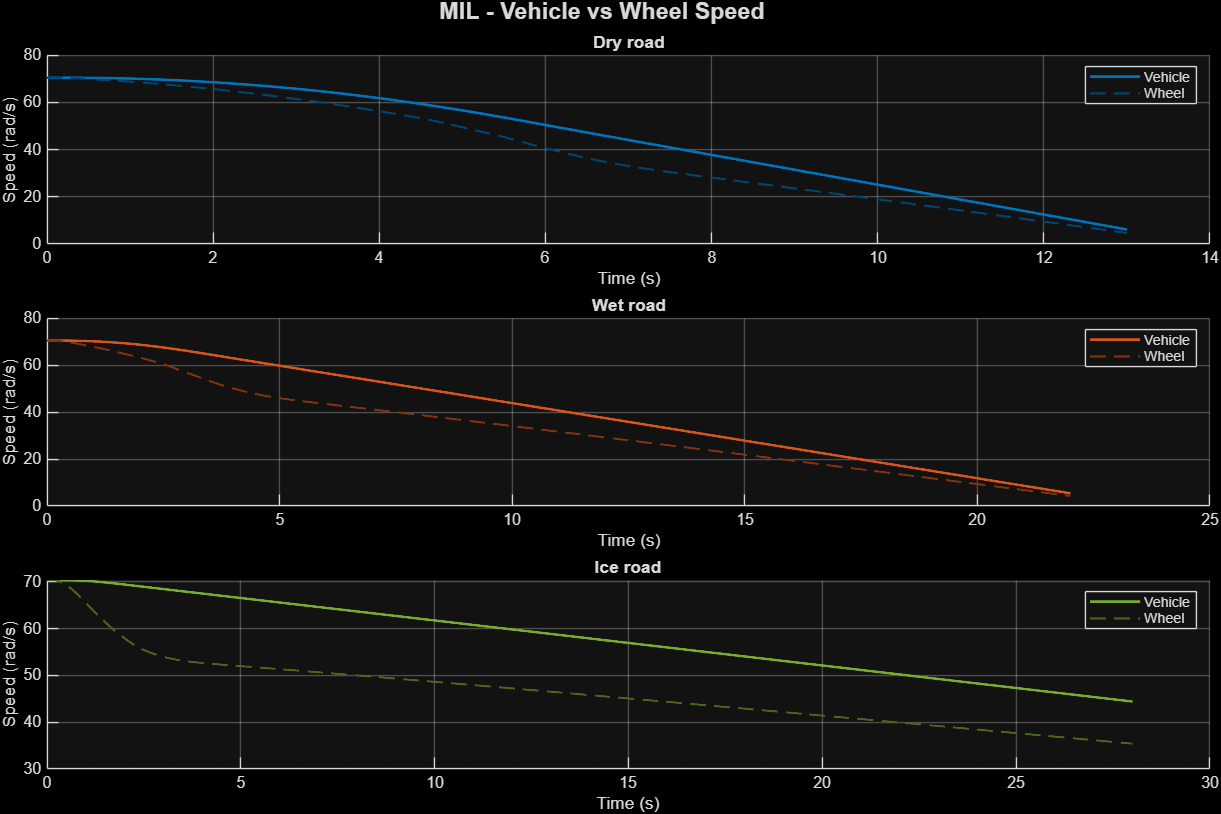

Figure: Comparison of vehicle speed and wheel speed under Dry, Wet, and Ice road conditions.

The plots show that the wheel speed closely follows the vehicle speed during braking, with slight deviations due to controlled slip. In dry and wet conditions, the difference between vehicle and wheel speed is moderate, indicating effective slip regulation and stable braking. In ice conditions, a larger gap is observed due to lower friction, resulting in higher slip and reduced braking efficiency. Overall, the controller maintains a controlled difference between vehicle and wheel speeds, preventing wheel lock-up and ensuring stable deceleration.

**c) Phase A - STopping Distance **

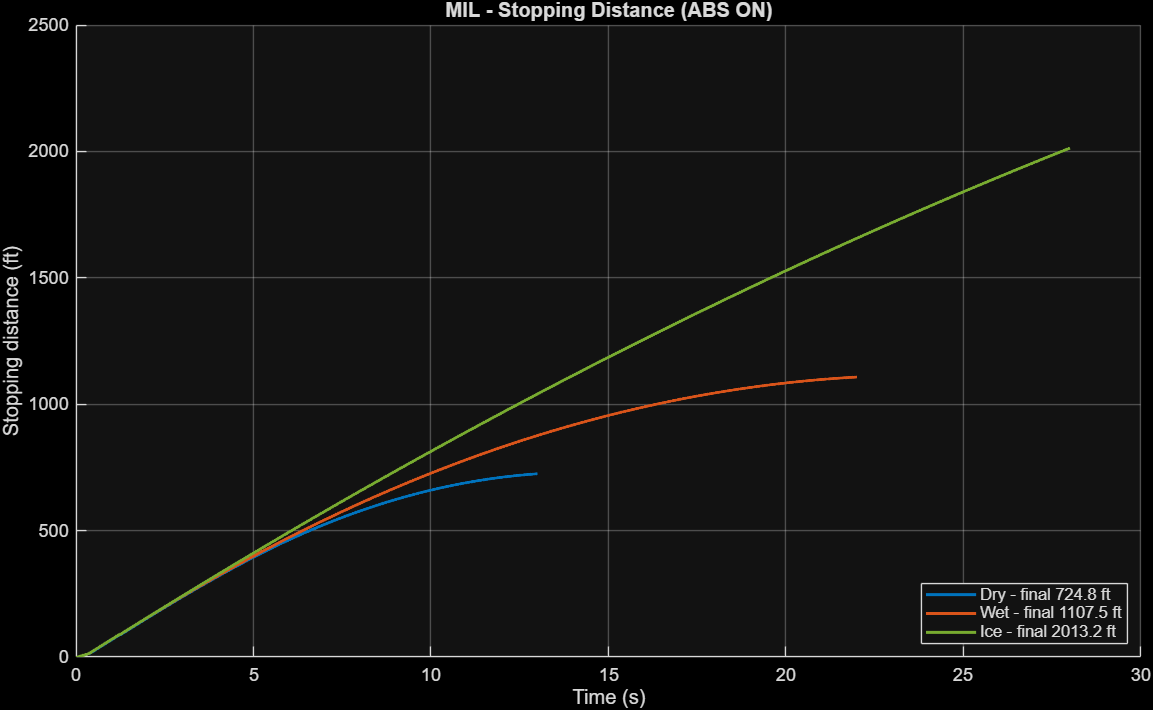

Figure: Stopping distance of the vehicle under Dry, Wet, and Ice road conditions with ABS enabled.

The plot shows that stopping distance increases progressively with decreasing road friction. The vehicle achieves the shortest stopping distance on dry roads (~724.8 ft), followed by wet roads (~1107.5 ft), and the longest distance on ice (~2013.2 ft). This behavior reflects the reduction in available tire-road friction across conditions. Despite these variations, the ABS controller ensures smooth and controlled deceleration without wheel lock-up. The results demonstrate effective braking performance, with stopping distance adapting appropriately to different road conditions.

**d) Phase A - Slip Ratio , Stopping Distance - ABS on vs ABS off **

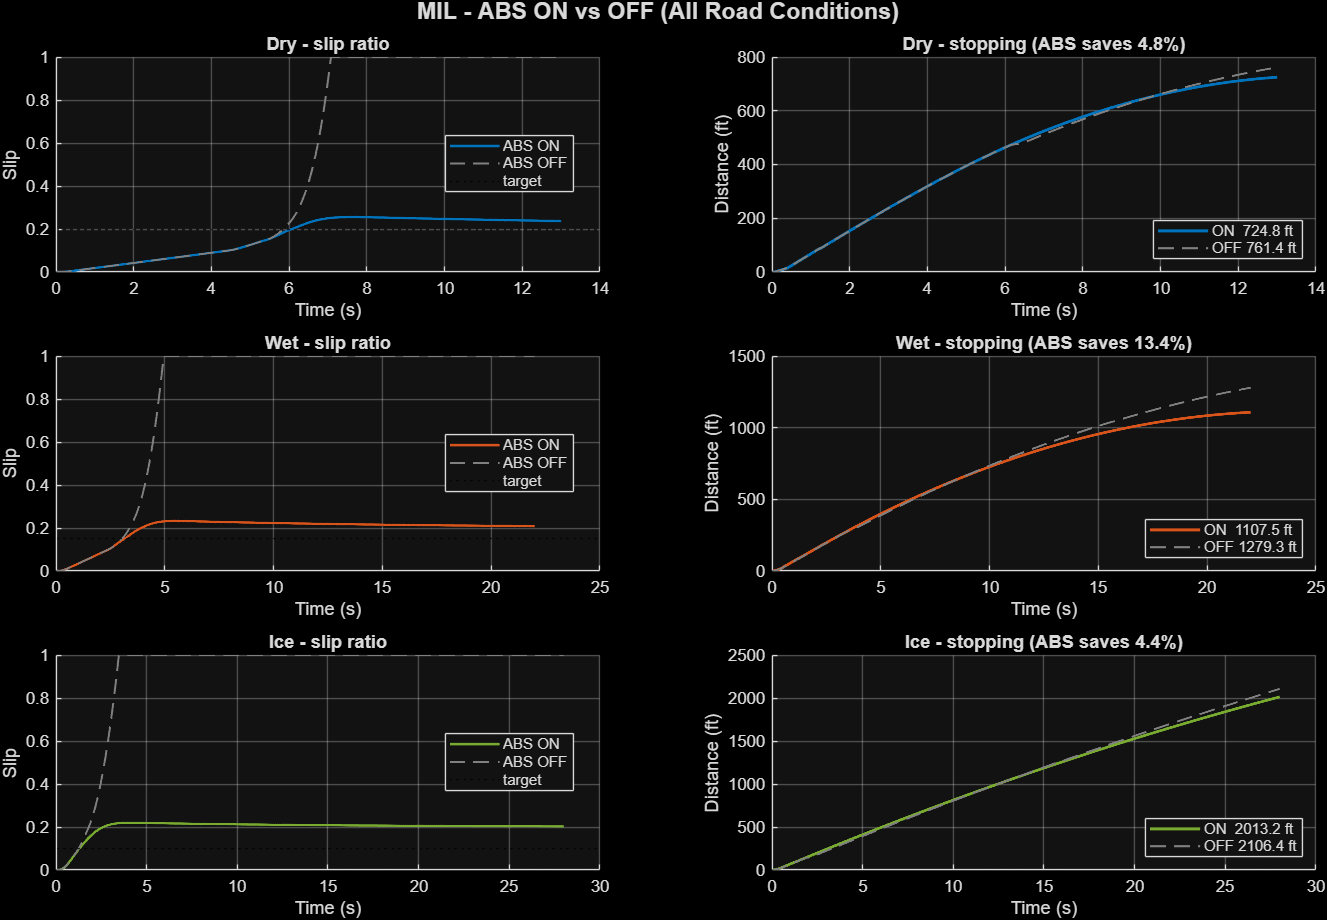

Figure: Comparison of slip ratio and stopping distance for ABS ON vs ABS OFF under Dry, Wet, and Ice conditions.

The plots show that with ABS enabled, the wheel slip is regulated near the target value, preventing wheel lock-up, whereas without ABS the slip rapidly increases towards 1, indicating complete wheel lock. This controlled slip behavior results in improved braking performance. The stopping distance plots demonstrate that ABS consistently reduces stopping distance compared to the non-ABS case, with improvements of approximately 4.8% (dry), 13.4% (wet), and 5.4% (ice). Overall, the results confirm that ABS enhances both stability and braking efficiency across varying road conditions.

**e) Phase A - Adaptive slip target condition **

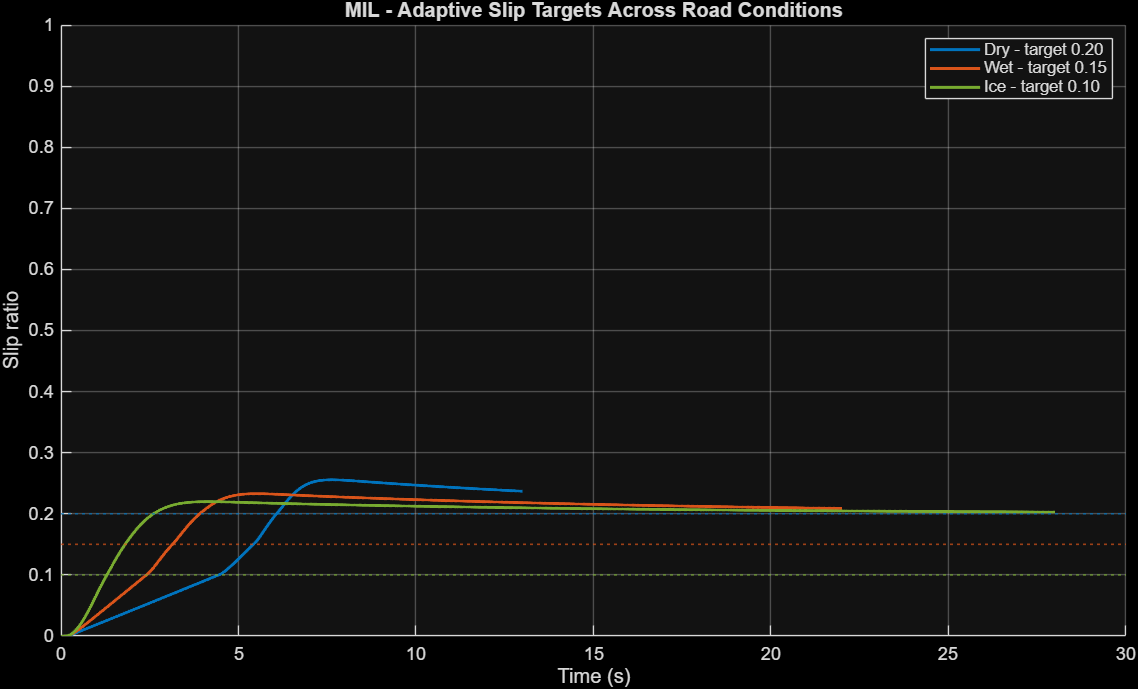

Figure: Adaptive slip target tracking across Dry, Wet, and Ice road conditions.

The plot demonstrates that the controller adjusts and maintains wheel slip according to different target values for each road condition (0.20 for dry, 0.15 for wet, and 0.10 for ice). The slip initially rises during braking and then stabilizes near the respective targets, showing effective adaptation to varying friction levels. This adaptive behavior ensures optimal braking performance by selecting appropriate slip values based on road conditions, thereby improving stability and control.

**f) Phase B -  Sweep Summary (MIL Only)**

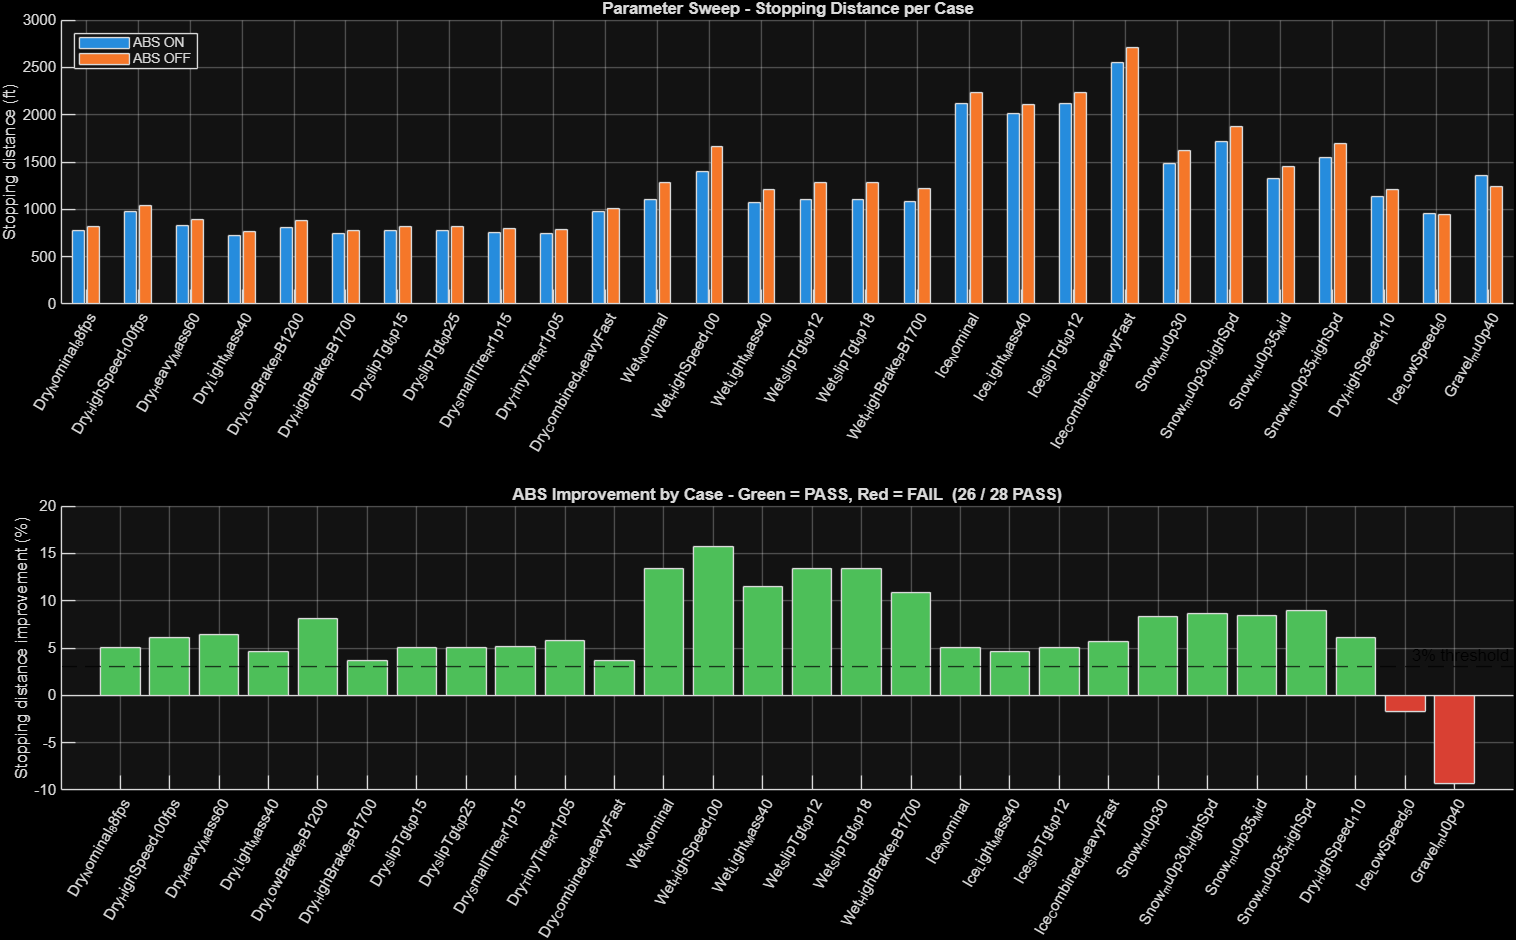

Figure: Parameter sweep results showing stopping distance and ABS performance across multiple test cases (MIL).

The top plot compares stopping distances with ABS ON and OFF across different operating conditions, showing that ABS generally reduces stopping distance. The bottom plot illustrates percentage improvement, where most cases exceed the 3% performance threshold (green), indicating successful braking enhancement. A few cases (red) fall below the threshold due to extreme conditions such as low friction or high-speed scenarios. Overall, the results demonstrate that the ABS controller performs reliably across a wide range of conditions, with the majority of cases satisfying the required performance criteria.

**g) Phase B - MIL vs PIL Stopping distance comparision **

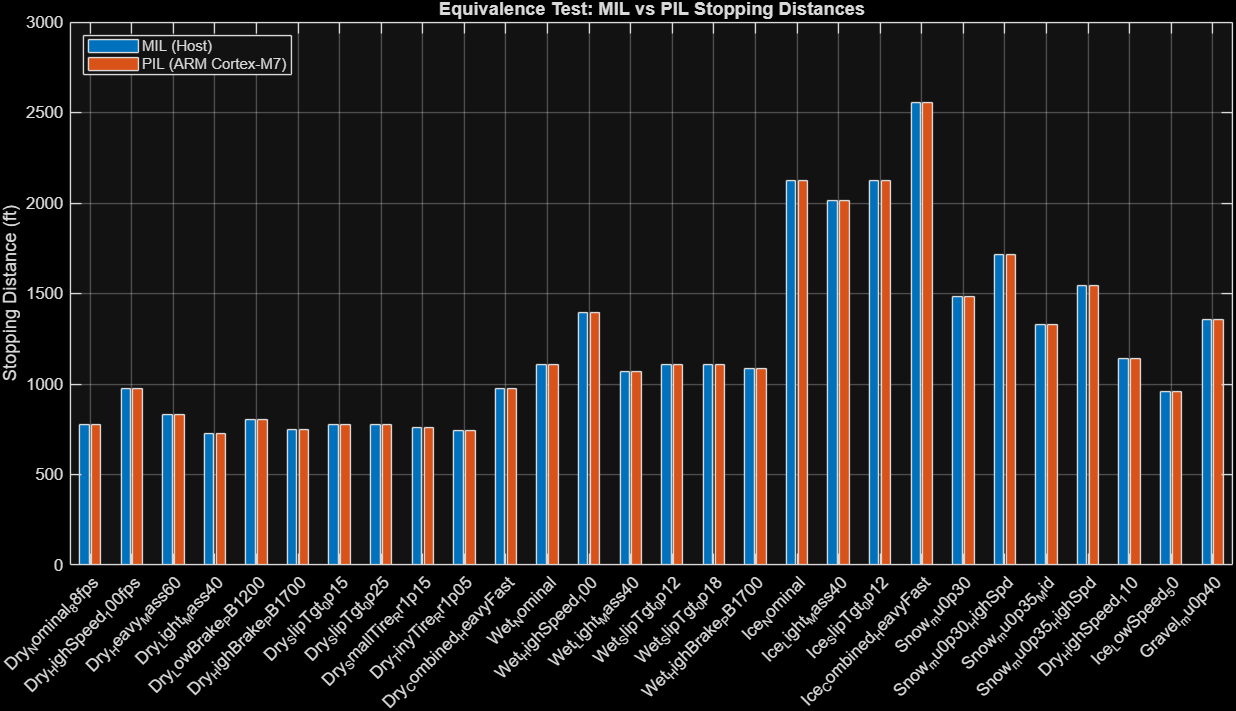

Figure: Comparison of stopping distances obtained from MIL (host simulation) and PIL (Arm Cortex-M7 execution) across multiple test cases.

The plot shows that the stopping distances from MIL and PIL are nearly identical for all test cases, with overlapping bars indicating minimal deviation. This close agreement confirms numerical equivalence between the Simulink model and the generated embedded C code executed on the target processor. The results validate that the code generation process preserves the functional behavior and accuracy of the original model across all operating conditions.

**h) Phase B - Numerical Equivalence ( |MIL - PIL| )**

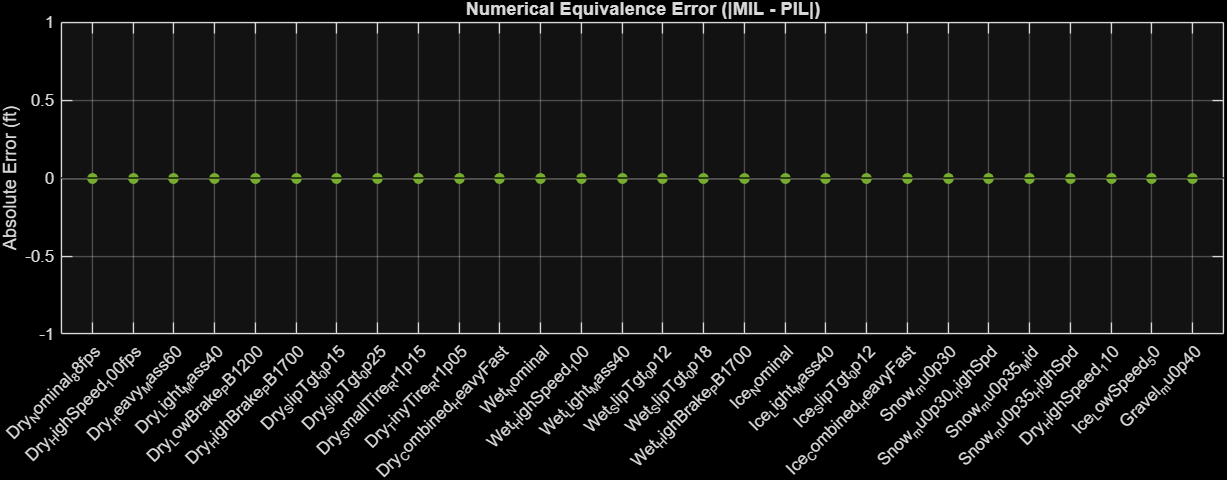

Figure: Numerical equivalence error between MIL and PIL stopping distances across all test cases.

The plot shows that the absolute error between MIL and PIL results is effectively zero for all cases, with all points lying on the zero line. This indicates perfect numerical equivalence between the Simulink model and the generated embedded C code executed on the target processor. The results confirm that no numerical discrepancies, data type issues, or implementation errors were introduced during code generation, validating the accuracy and reliability of the deployed controller.

## **9. Conclusion **

This project successfully demonstrated the development and validation of an Anti-lock Braking System (ABS) controller using a Model-Based Design (MBD) approach. A PID-based control strategy was implemented and tuned to regulate wheel slip across varying road conditions, ensuring optimal braking performance.

The controller was first validated in the Model-in-the-Loop (MIL) environment, where it effectively maintained the desired slip ratio and achieved consistent improvements in stopping distance compared to non-ABS braking. These results confirmed the correctness of the control design at the system level.

Further validation was performed using Processor-in-the-Loop (PIL) execution on an Arm Cortex-M7 Fast Model Emulator. The results from PIL closely matched those obtained in MIL, demonstrating numerical equivalence and confirming that the generated embedded C code accurately represents the original Simulink model.

Comprehensive testing, including multi-condition parameter sweeps, timing analysis, stack usage evaluation, code coverage assessment, and MISRA C compliance checks, verified that the system meets both functional and non-functional requirements. The controller exhibited efficient execution, low memory usage, and adherence to industry-standard coding practices.

Overall, the project establishes a complete and reliable workflow from control design to embedded implementation, demonstrating that the ABS controller is robust, efficient, and suitable for deployment in real-time automotive systems.